% Contributors: Mustafa Saraoğlu, Laura Slabon, Erik Noack, Müjdat Korkmaz, Marta Valdes Martin

# Before Getting Started

Before starting with the documentation, please read the **README.md** file located at the root of the project directory.

# Getting Started with MOBATSim

MOBATSim (Model-based Autonomous Traffic Simulation Framework) is a framework based on MATLAB® and Simulink® that allows users to develop automated driving algorithms and assess their safety and performance. By running a traffic simulation, the safety of the implemented component or algorithm can be measured on both the vehicle level and the traffic level, supported by 2D and 3D visualization options.

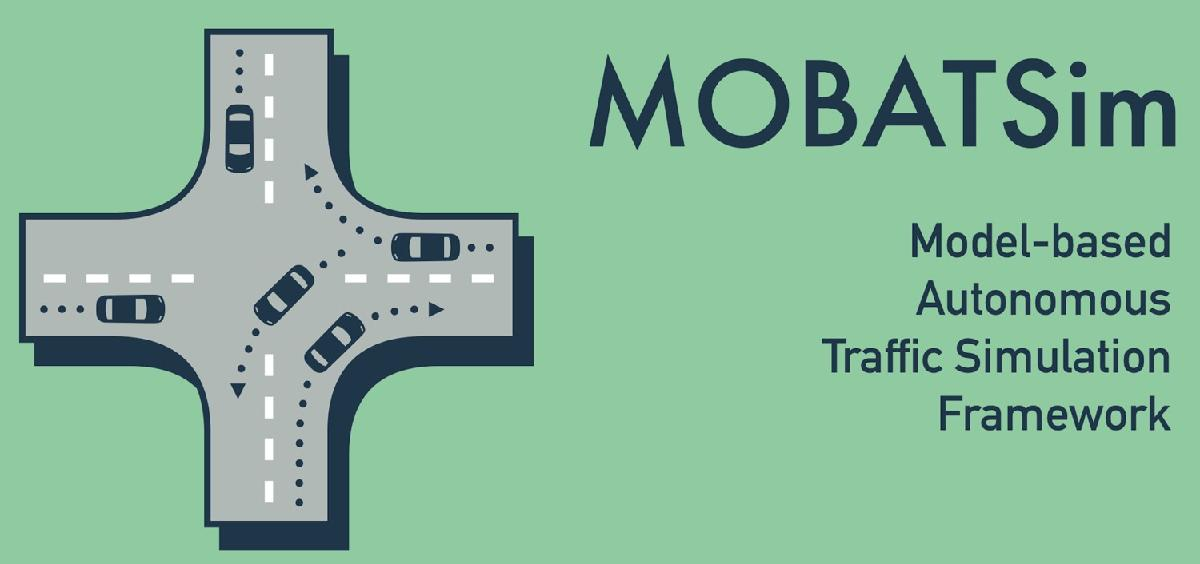

# The Structure of the MOBATSim Documentation

MOBATSim consists of several modular elements, ranging from MATLAB code to Simulink models, a Graphical User Interface (GUI), and live script documentation that includes LaTeX formulas and explanations of specific components of MOBATSim. Given the complexity of the documentation, fitting everything into a single live script would be exhaustive. Therefore, we have decided to split the documentation into several separate live script files, each focused on a specific subject and level of detail.

Once the **"GettingStarted.mlx"** document is completed, the overall structure of MOBATSim and how it works will be easier to understand. The next step is to review the **"Documentation.mlx"** file, which provides more detailed information about MOBATSim, focusing on its implementation and functionality. Based on the areas of interest, additional documentation files can be explored. For example, information on the implementation of vehicle models is available in **"VehicleMotionPlanningControl.mlx"**, and details about how the map is generated and visualized can be found in **"MapStructureVisualization.mlx"**.

# Starting the Simulation and Visualization

MOBATSim includes a project file that contains the Simulink files and their paths. To open the project, double-click on **MOBATSim.prj**. A GUI will appear, which can be used to start the simulation. Simply click the **Start Simulation** button and wait for the simulation to begin.

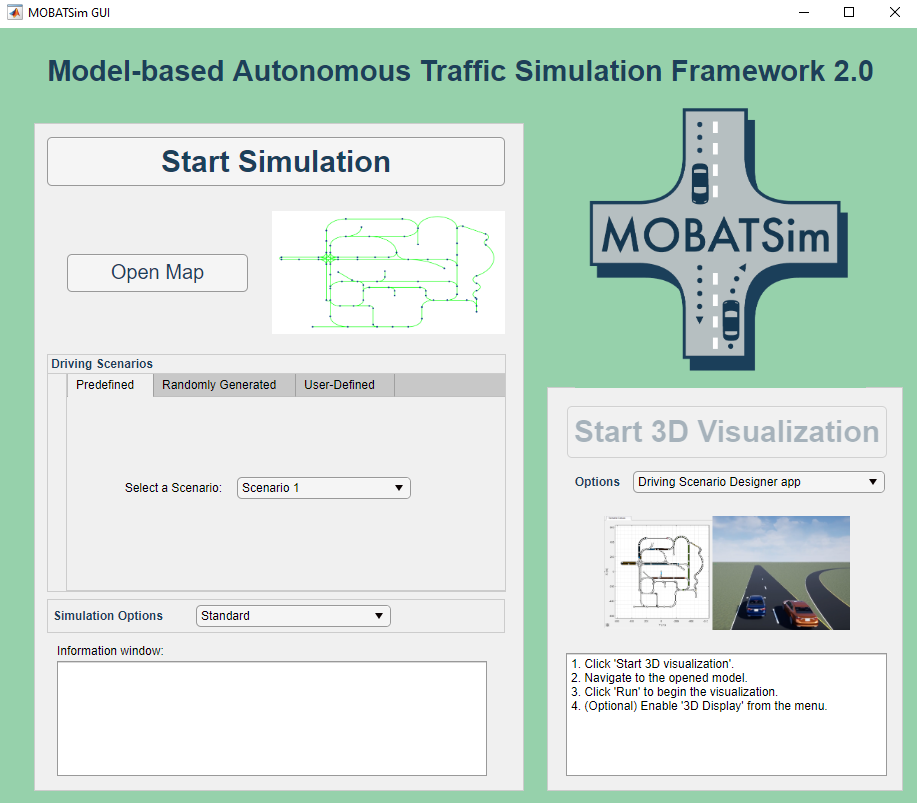

The MOBATSim Simulink model will automatically open and run to start the simulation. The map consists of nodes and edges displayed on a 2D plot. Vehicles appear as red circles, with their speeds shown in meters per second. Roads are represented in bright green, and the planned paths of the vehicles are dynamically highlighted in different colors. At this stage, the simulation runs using the Simulink model and the corresponding MATLAB m-files, while simultaneously logging vehicle data. Therefore, the simulation must be completed before the user can proceed with further visualization.

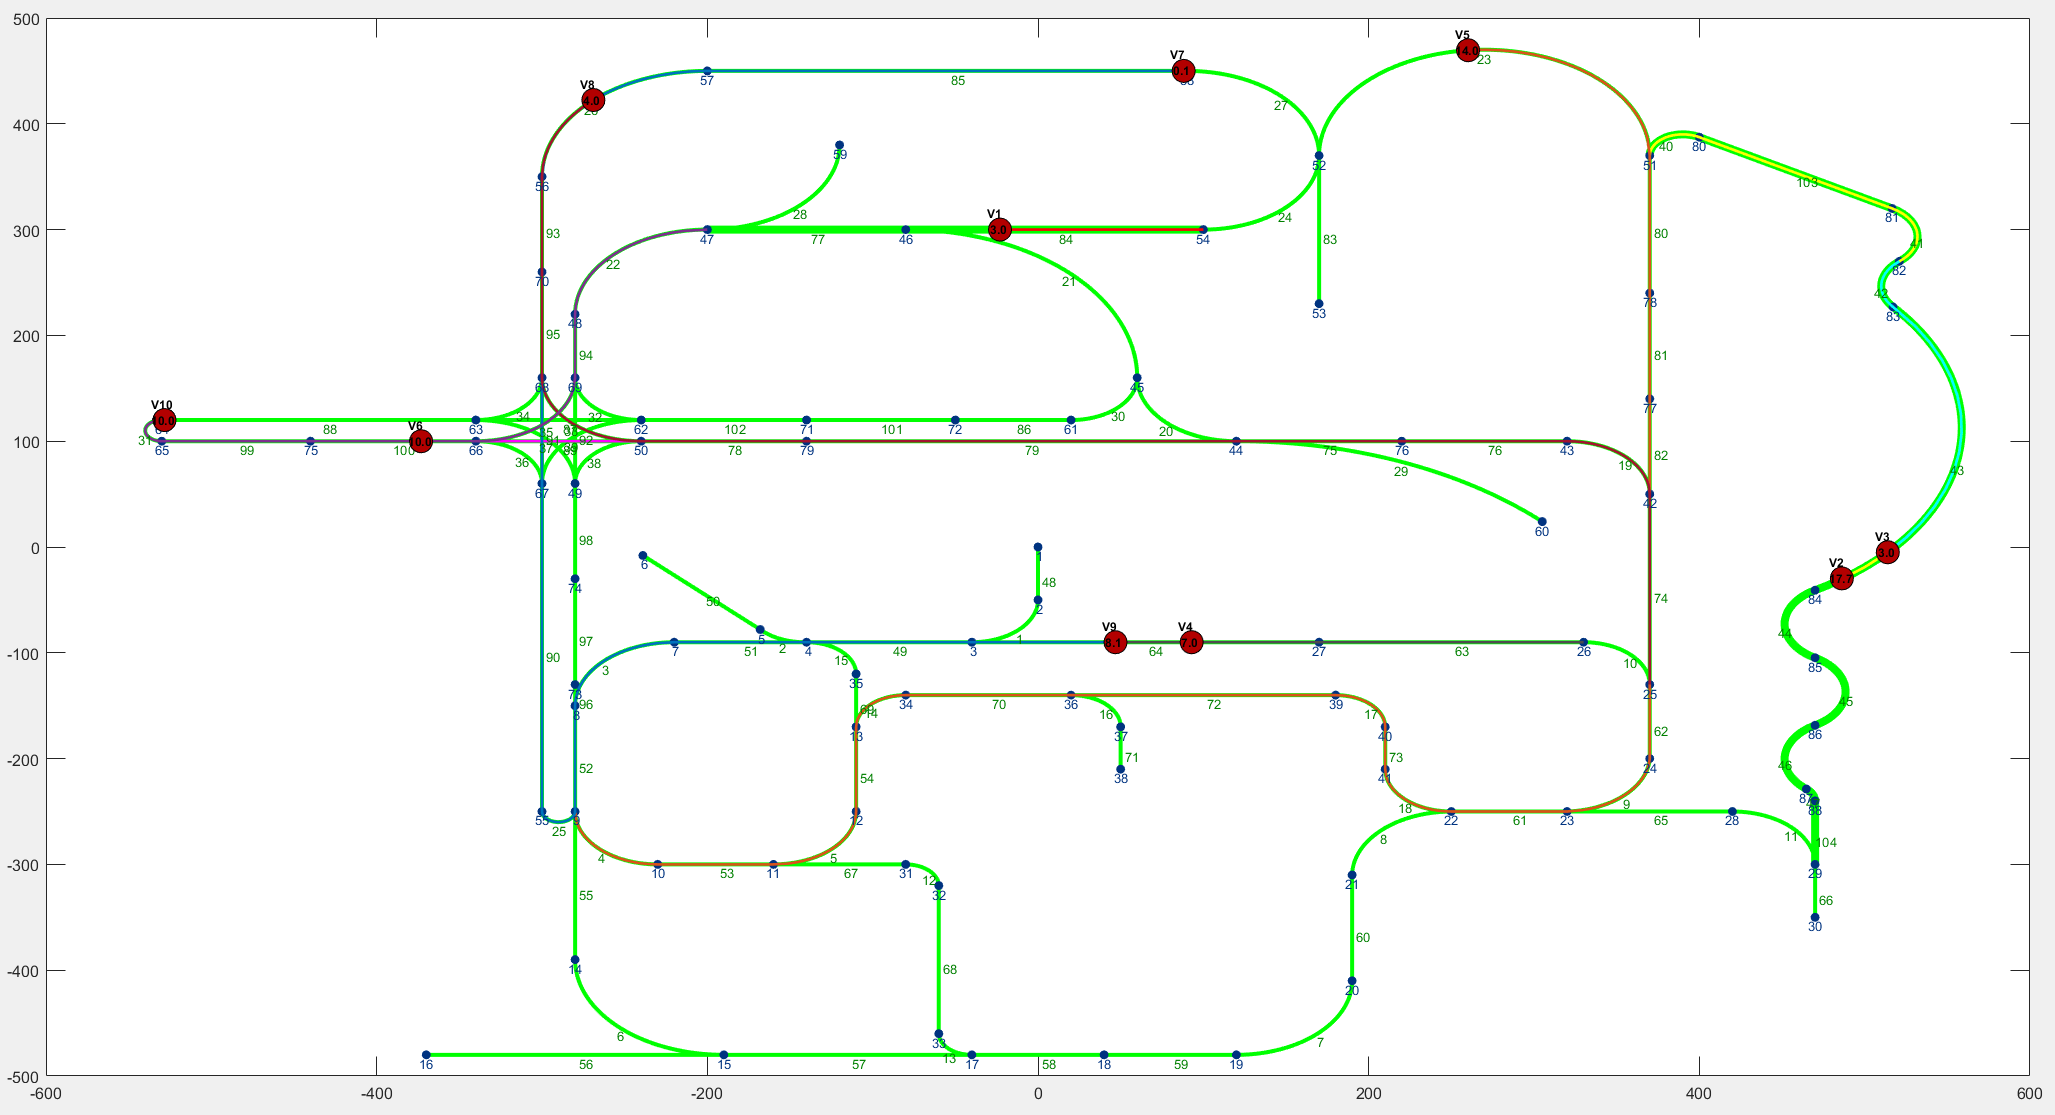

After completing the simulation without errors, the logged vehicle data, along with timestamps, is saved in the base workspace for further analysis or visualization. MOBATSim supports the following visualization options:

- **Using Driving Scenario Designer app**

- **Using Bird's-Eye Scope**

- **Simulink 3D Animation**

## **Using Driving Scenario Designer app**

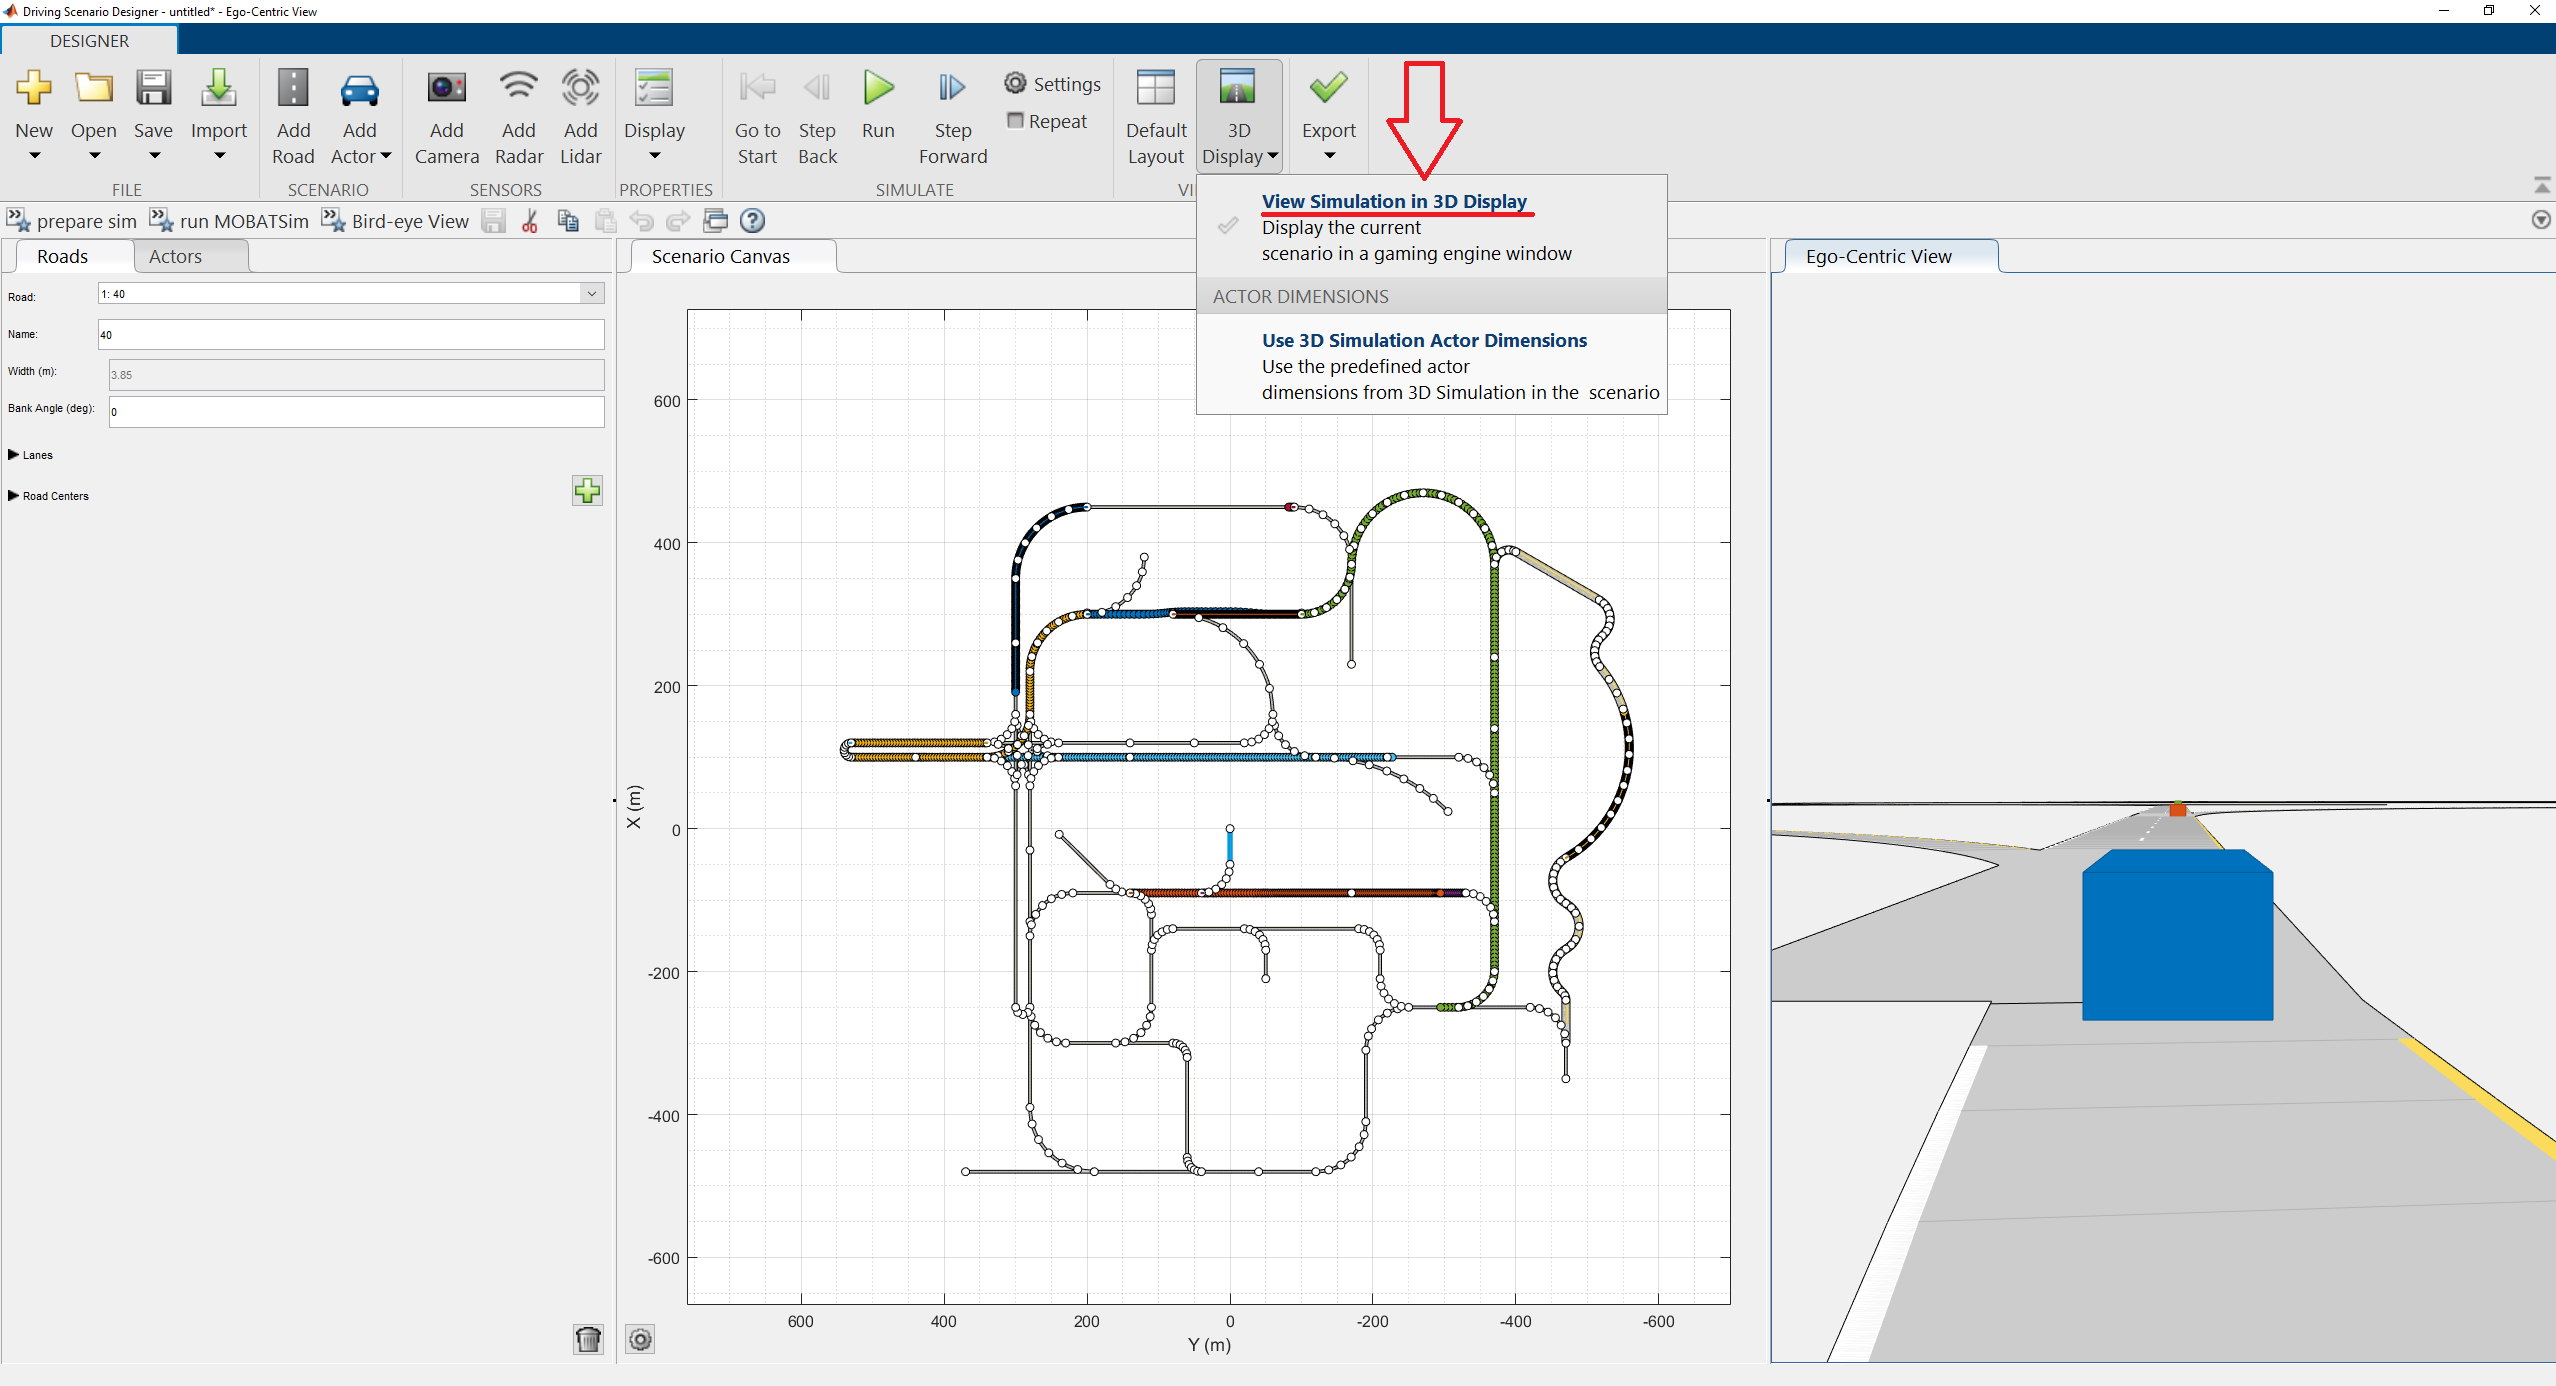

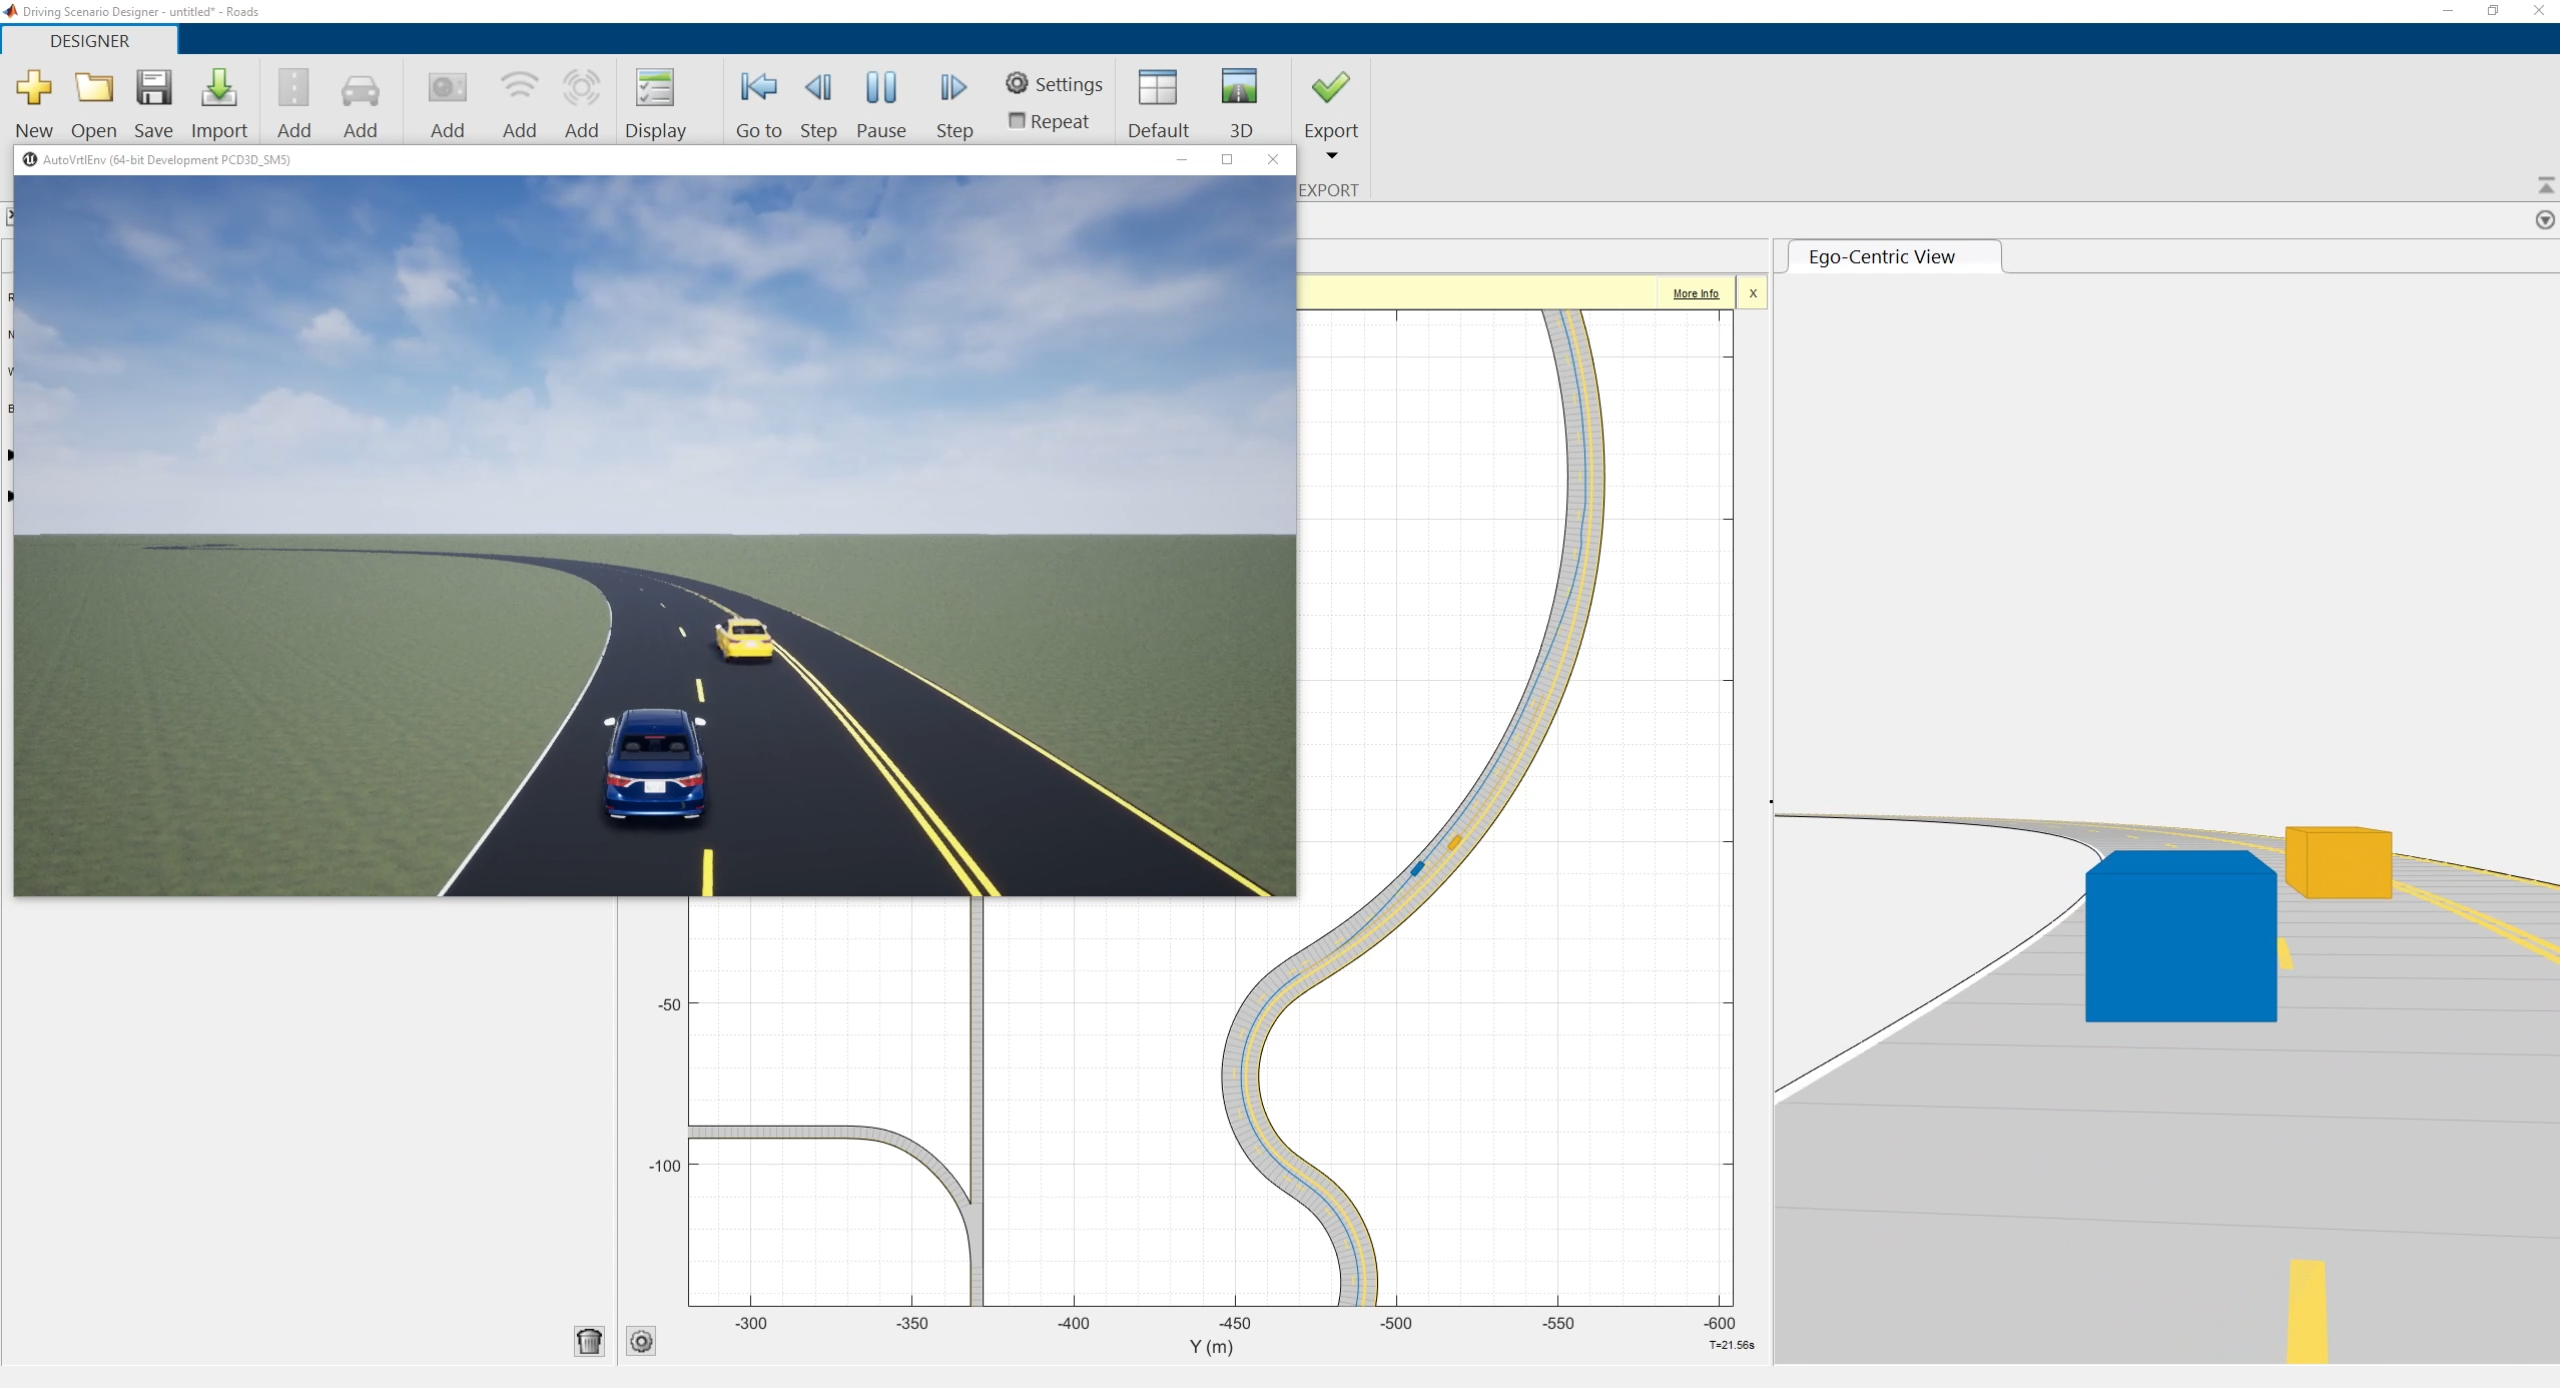

## Using Bird's-Eye Scope

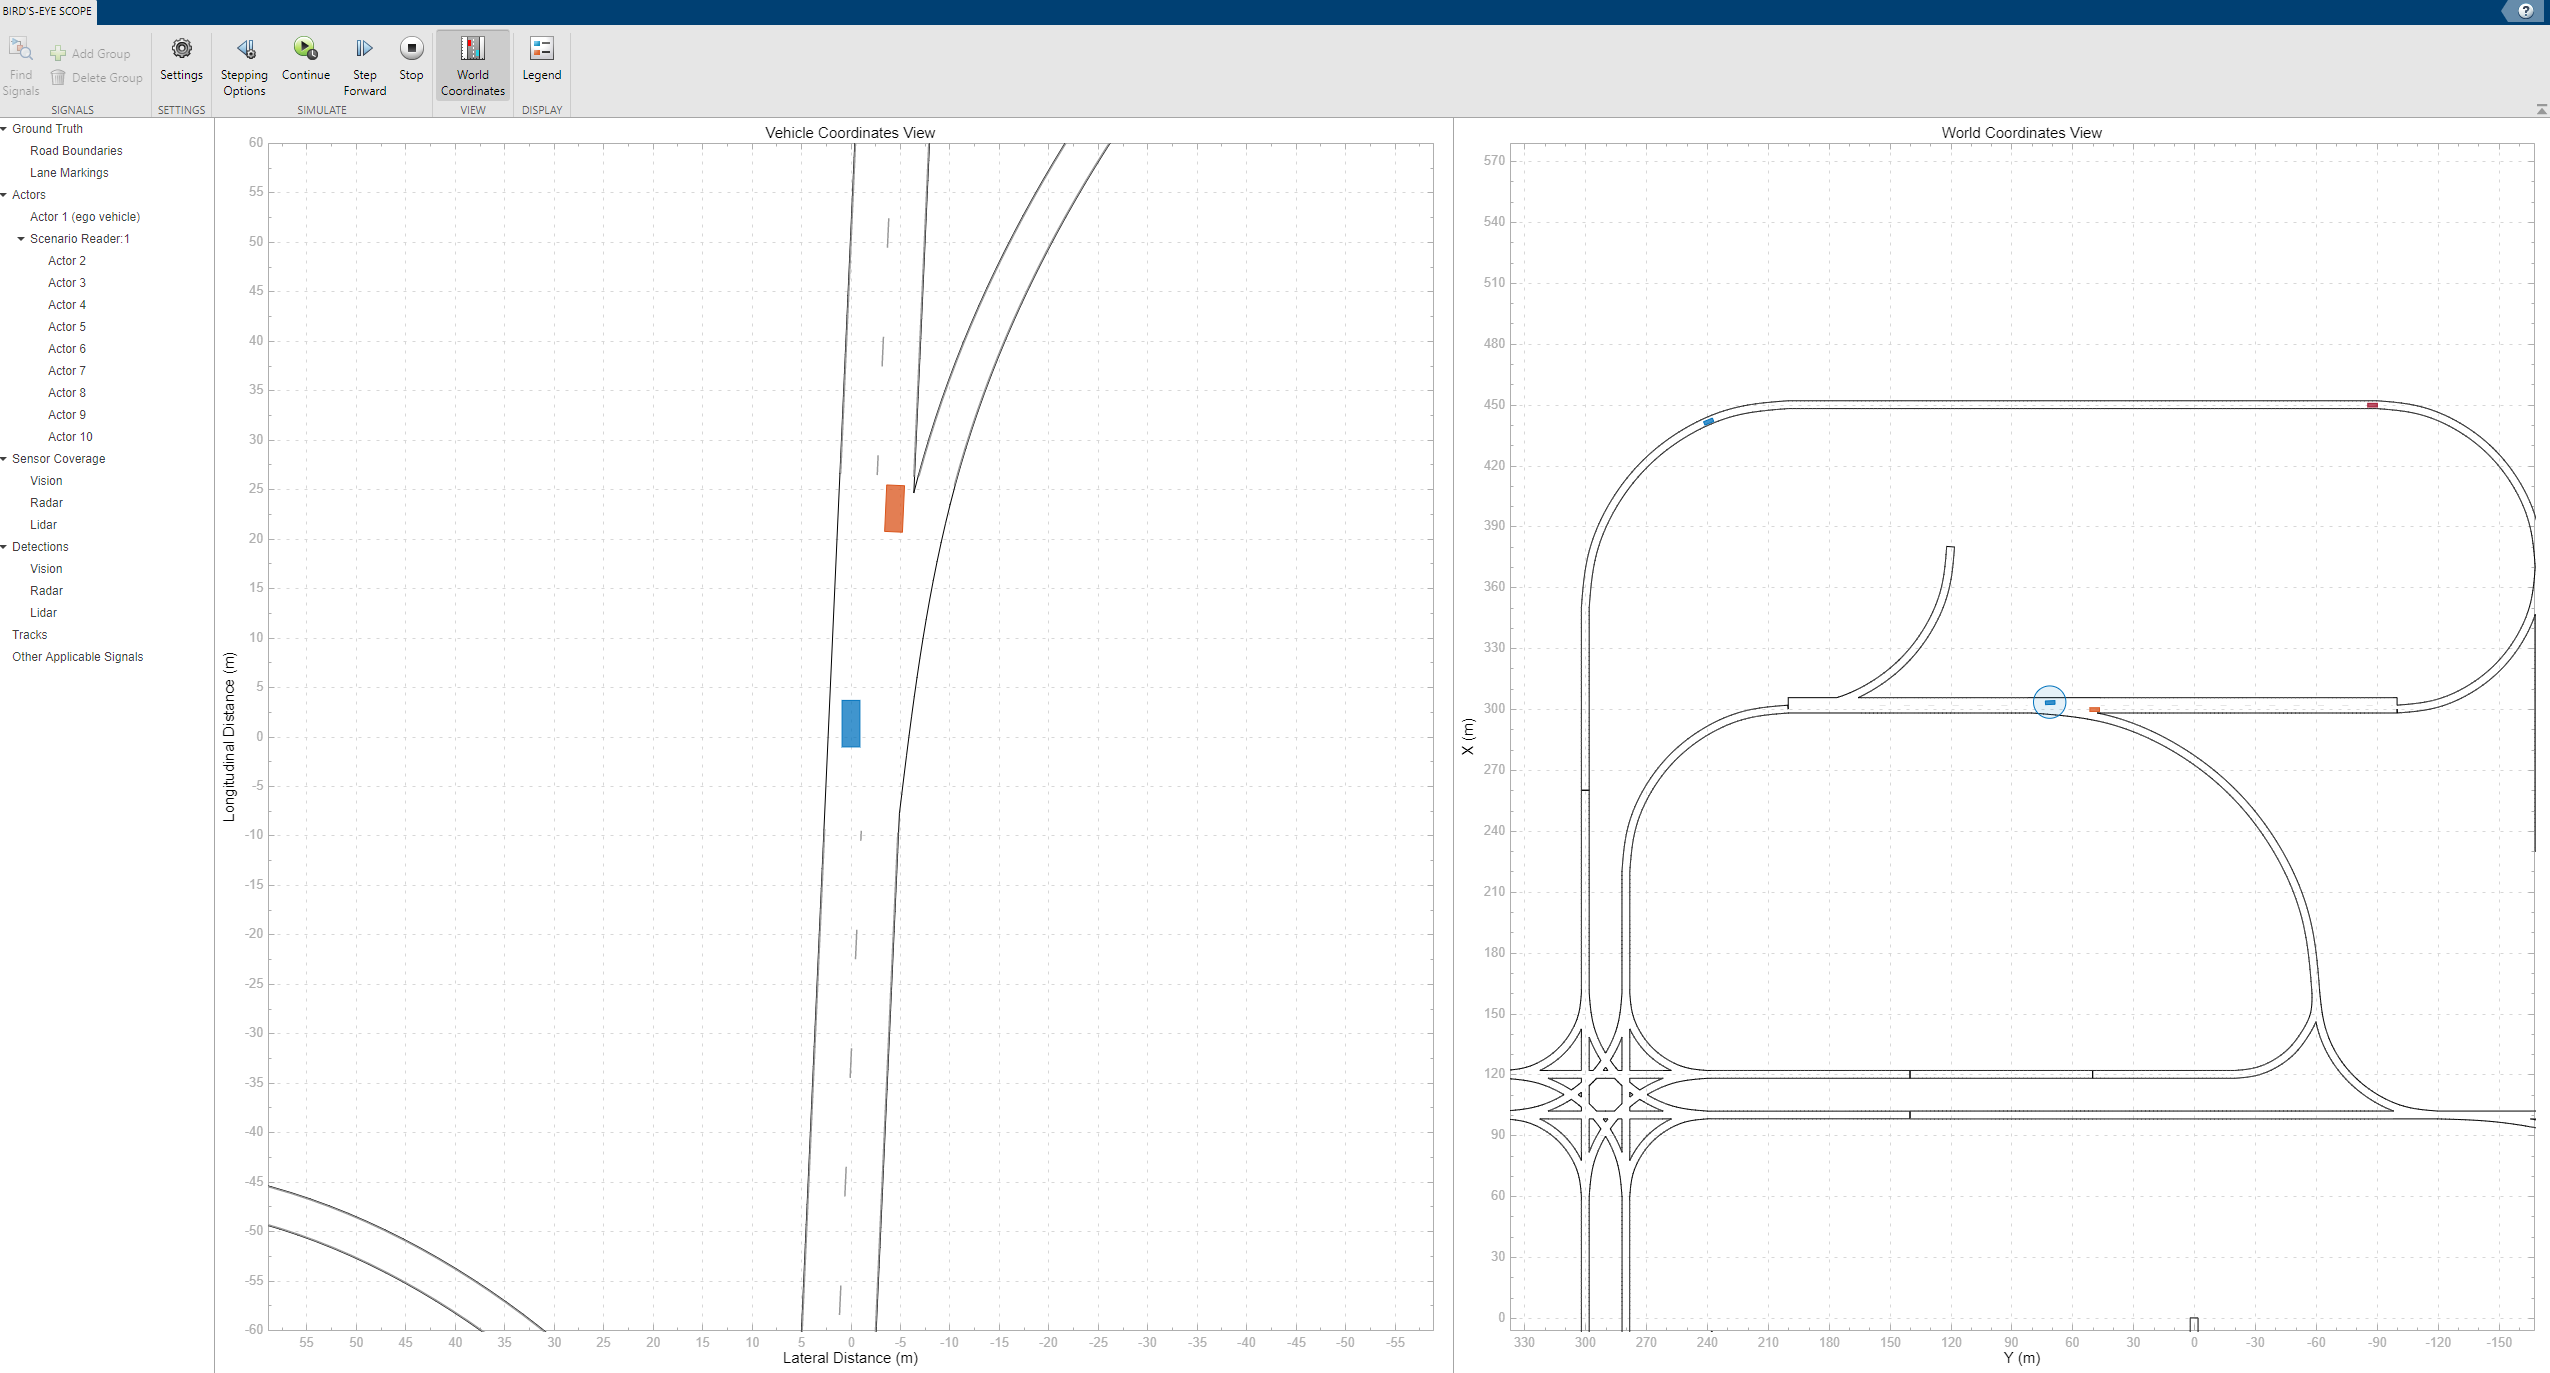

## Simulink 3D Animation

This map is obsolete, and the extended parts of MOBATSim, such as double lane roads, have not been applied to this map. Other visualization methods explained above are much more accurate and useful for scientific purposes.

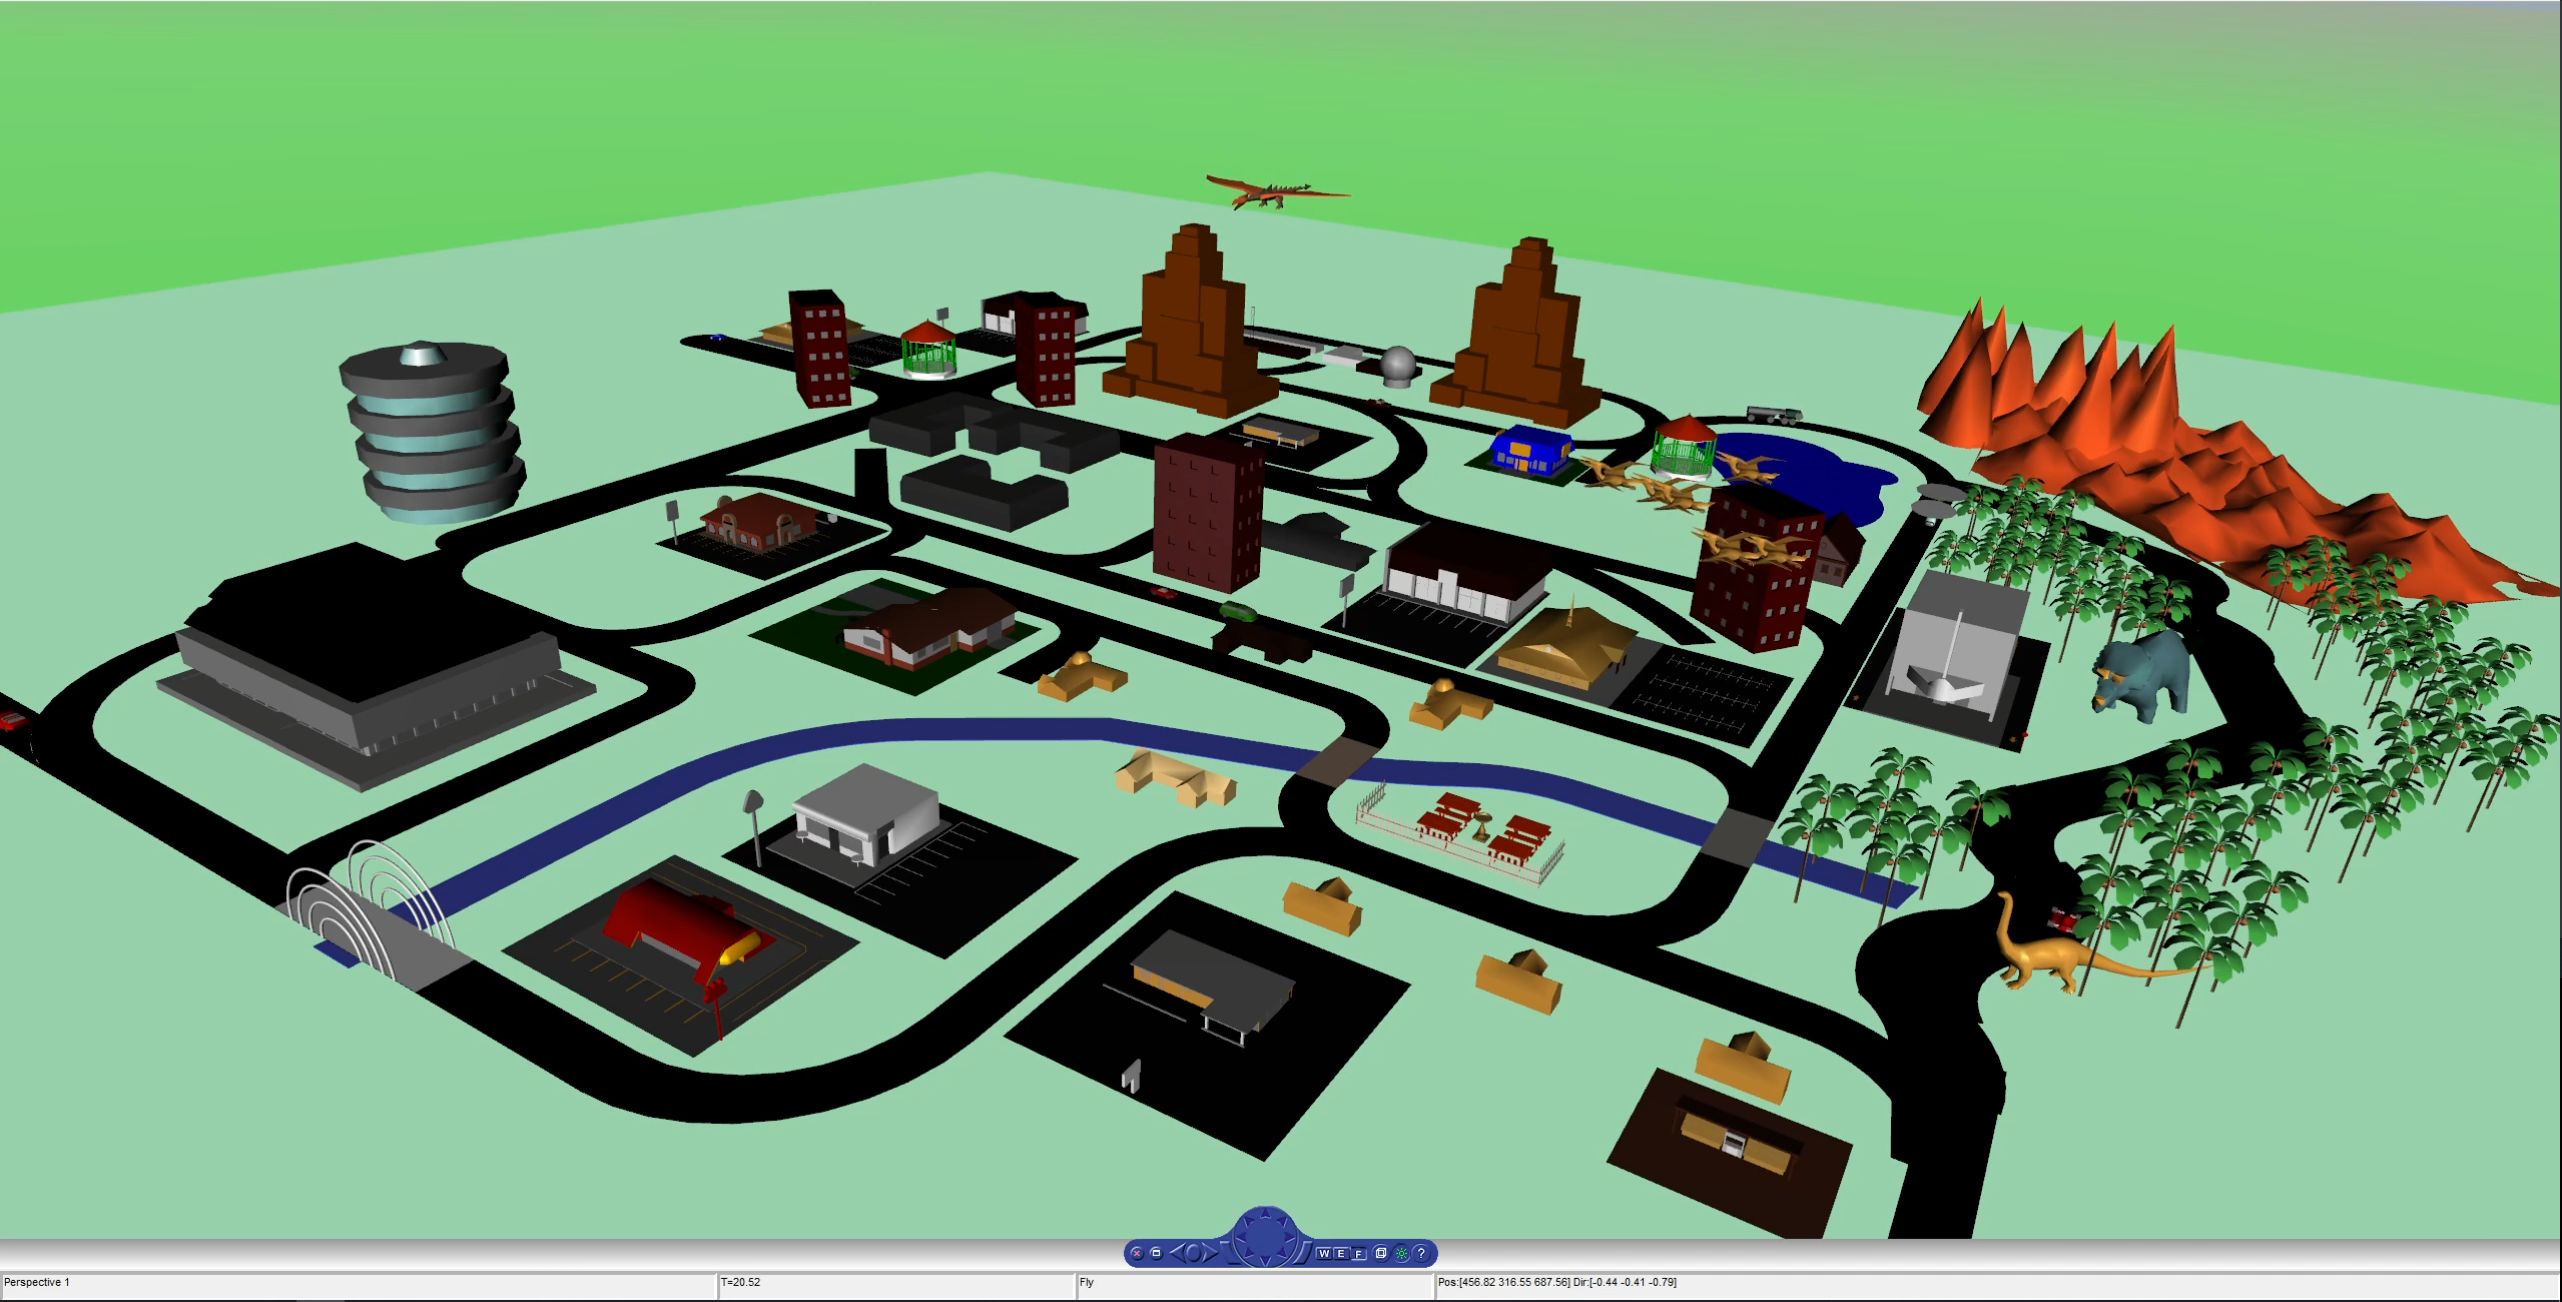

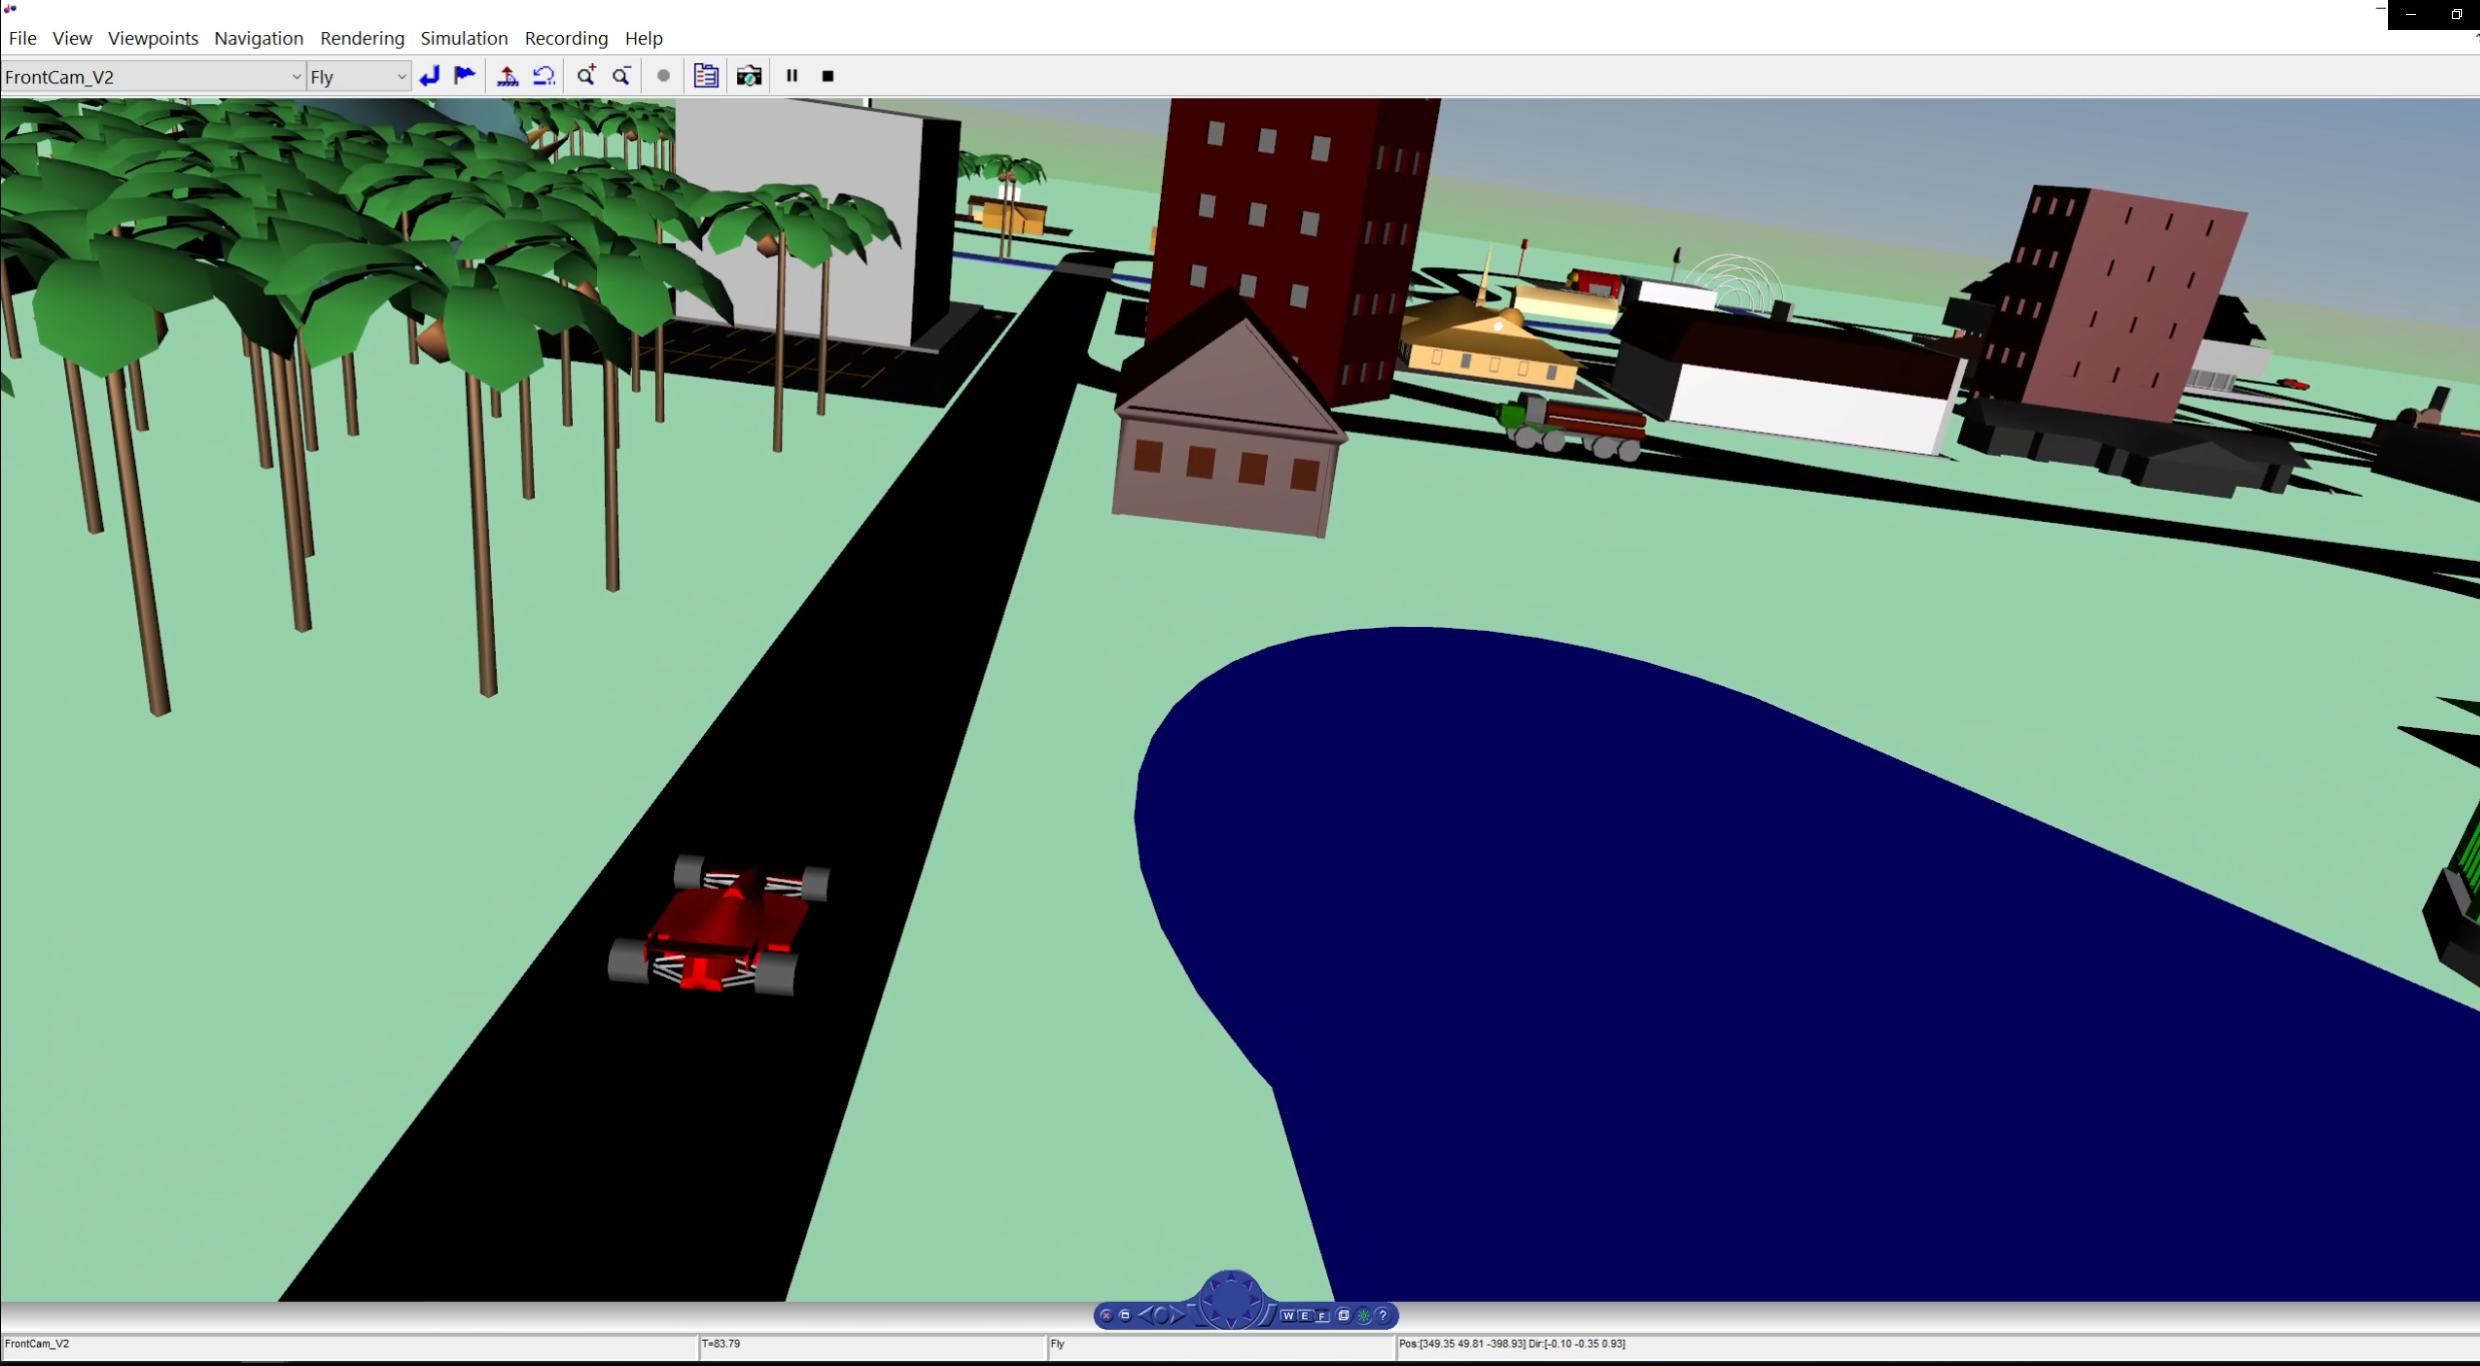

# -----------------------------------------------------------------------------

# Tutorials

Now you know how to run the simulation but the best way to learn how MOBATSim works is to interact with it and make changes. In the live script *docs/Documentation.mlx*, you will find a more detailed and in-depth workflow of MOBATSim. However the tutorials below are designed to provide you a quick intuition about MOBATSim without reading the whole documentation.

## 1- Change Vehicle initial Starting Points and Destination Points

Now go ahead and try to find the initial driving scenario file. A driving scenario defines the **starting points**, **destination points**, and the **maximum speeds** of the vehicles. You can simply look for the function:                                                 *src/Scripts/Load Data/load_scenario.m*. There you should see 10 starting points and destination points for 10 vehicles. Try to change some of them. Note that the roads are **one-way roads**, so the destination points should be reachable from the starting points. Otherwise, the path planner of the vehicle throws an error. Here is the portion of the code you can edit (it is commented out below with % to make sure that it doesn't get executed when you run this script as a whole):

After changing some of the **startingPoints**, **destinationPoints** and **maxSpeeds **go ahead and run the simulation with:

## 2- Debug the Simulation and View Vehicle States

The purpose of this task is to learn how the blocks and code work together. Let's start a simulation first and then try to pause it and view some of the state variables at a given time.

When you run the simulation, the MOBATSim Simulink model was opened. As mentioned before, a more detailed explanation of the elements below are given in *docs/Documentation.mlx*. Our task is to simply choose a block and interrupt it by placing a **conditional breakpoint**.

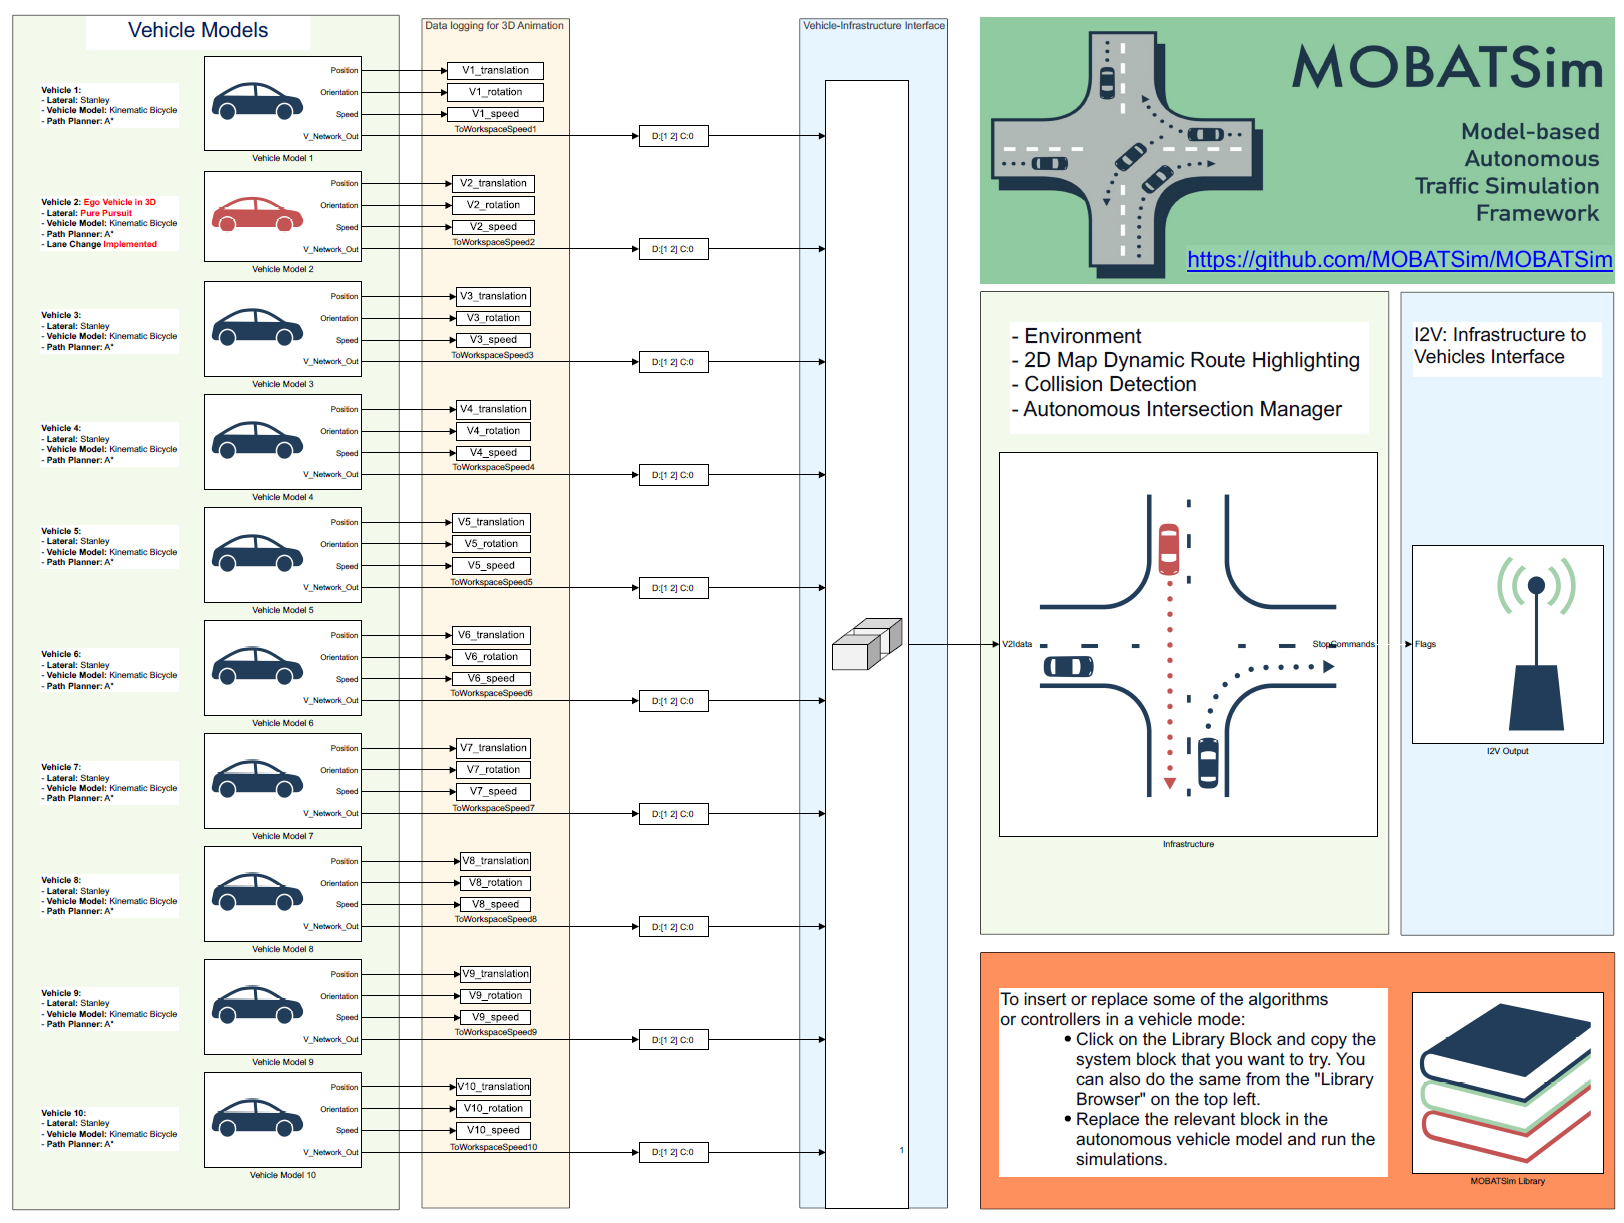

Let's zoom on **Vehicle Model 1** and left click on the bottom left corner (on the small arrow that appears) to **look under the Mask**.

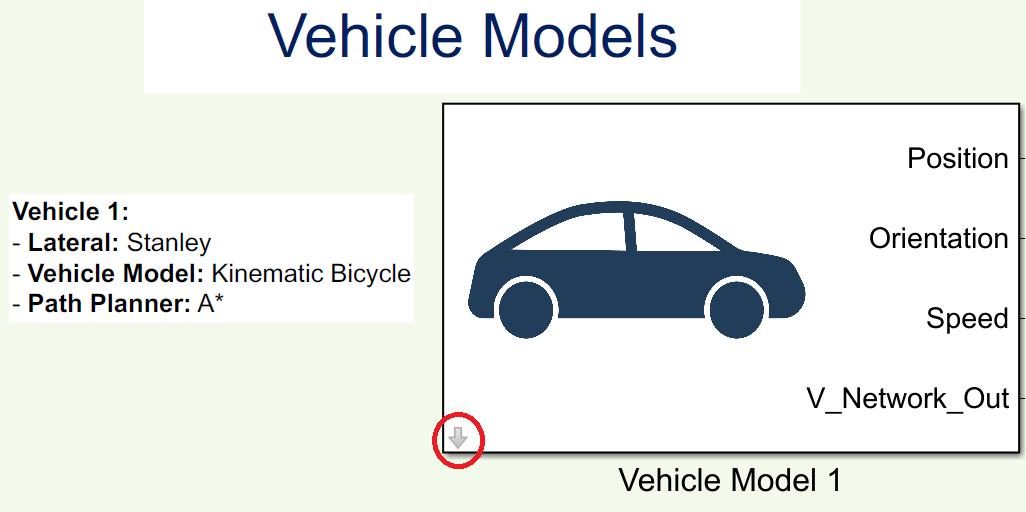

The autonomous vehicle architecture in MOBATSim is shown below. Here let's choose the **Behavioral Planner** to set a breakpoint. Double click on the **Behavioral Planner** block and a small window will appear. Since this block is a **MATLAB System Block**, it works like a **class** with **properties** and **methods**. From this window, you need to click on the source code to view the *src/VehicleDrivingMode.m* Class.

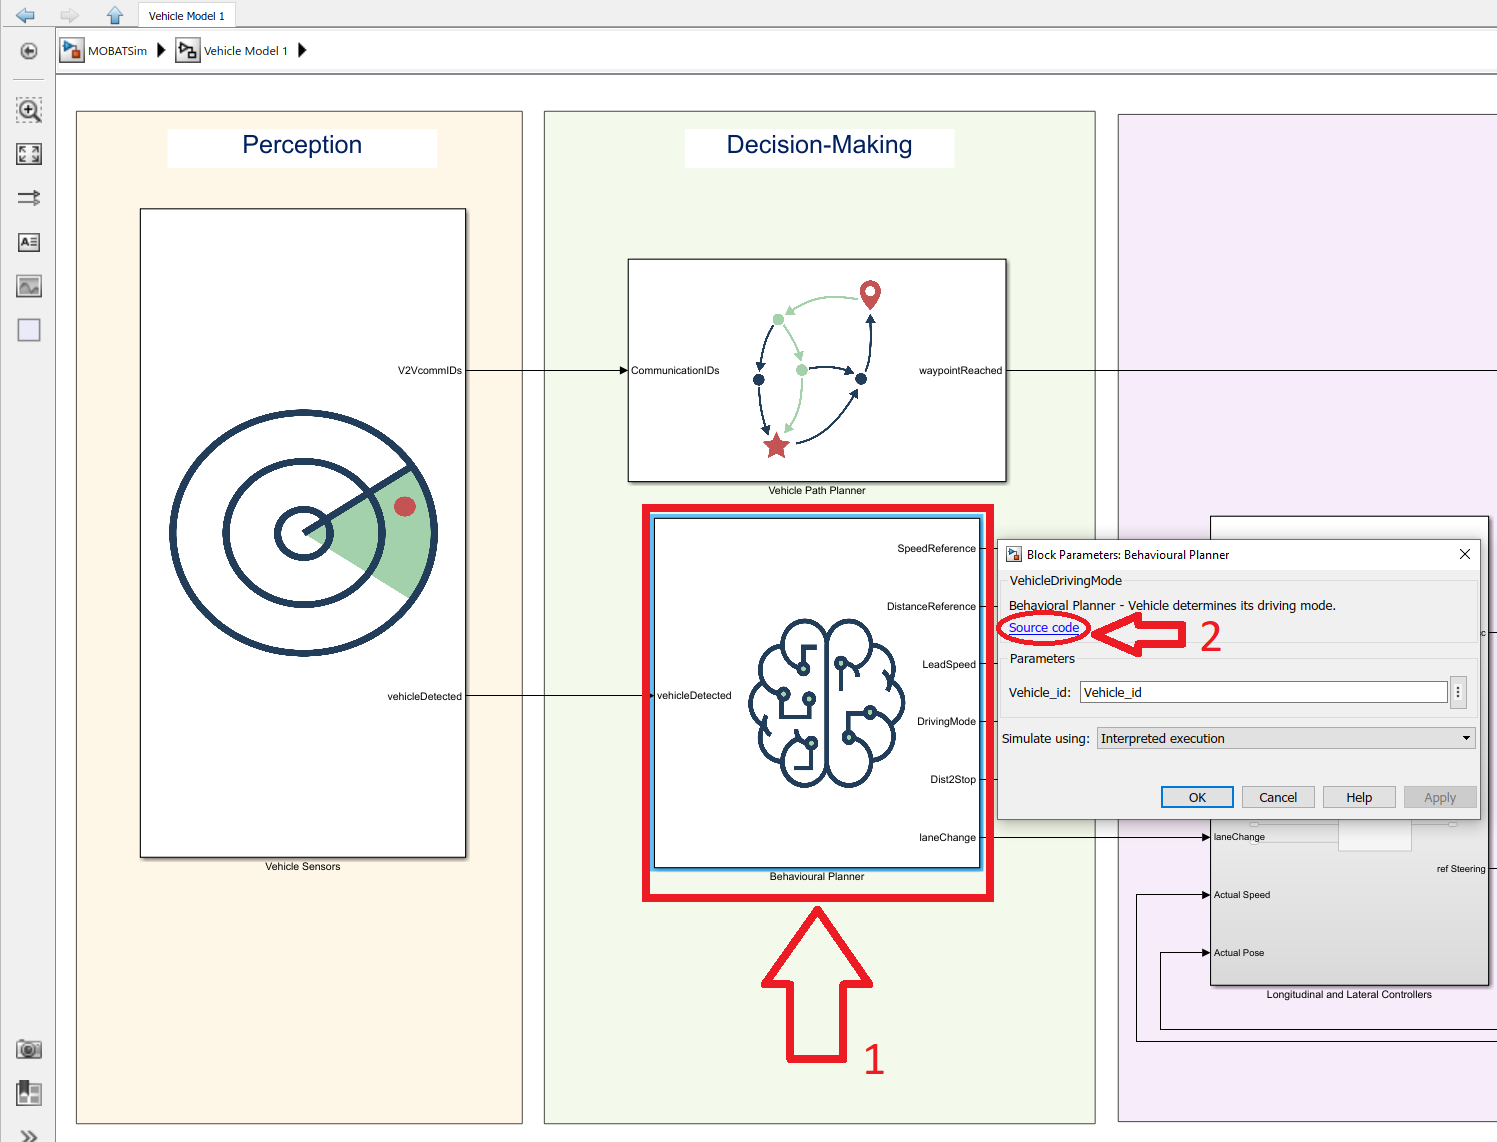

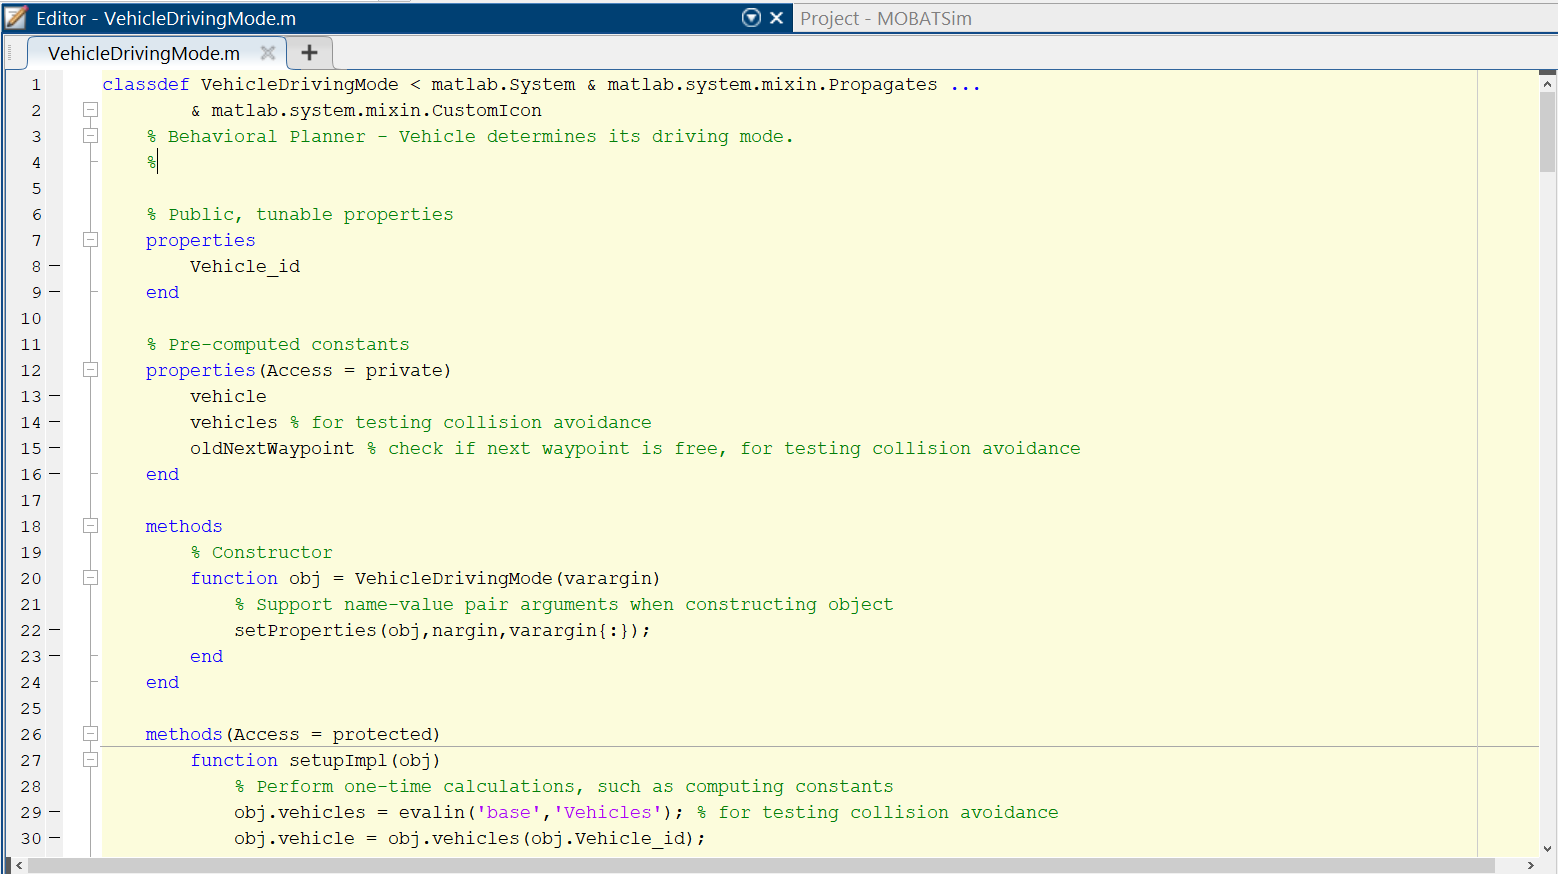

The `Vehicle_id` variable is the variable which keeps the IDs of different vehicles from getting confused by the program. The `MATLAB System Block` code seen in the editor acts as a `Class` in itself but with a different set of properties to support the Simulink block type of execution. In order to interrupt the block execution at a given time, we need to scrool down into the `stepImpl()` function which runs on the loop at every sample time.

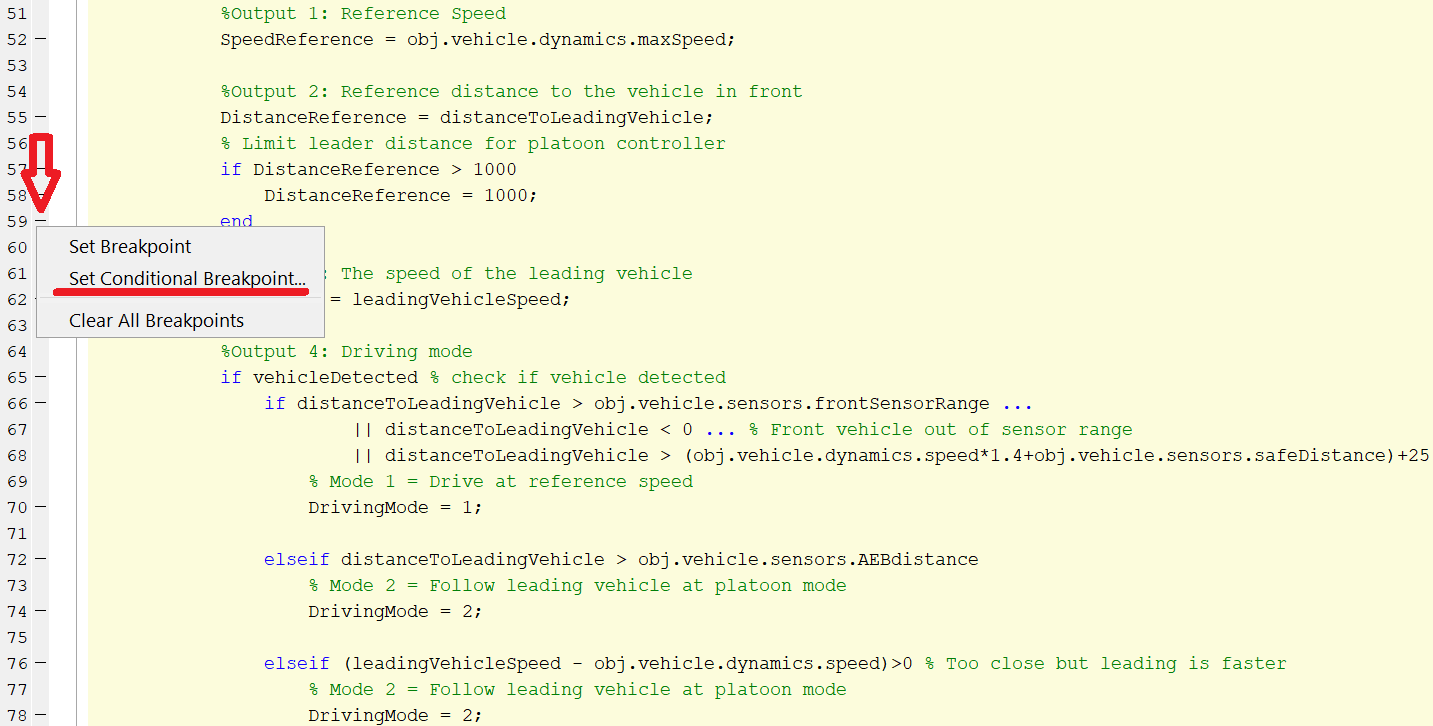

Let's put a conditional breakpoint on** line 65**. Right click on the dash next to number 65 on the left and then choose Set Conditional Breakpoint. A useful tip is to put conditional breakpoints to view the execution at a certain time.  For example, to see the states of **Vehicle 4** after time` t>6`, enter the following condition in the next window:

- `obj.vehicle.id == 4 && get_param('MOBATSim','SimulationTime')>6`

`Here obj.vehicle.id `refers to the ID of the vehicle that we want to get. The code `get_param('MOBATSim','SimulationTime')>6 `gets the simulation time of the Simulink model at every loop and checks if it is greater than 6. By putting an **and (**`&&`**) **between two conditions we are going to make sure that the simulation gets paused when **Vehicle 4** is executing the code after time `t>6`.

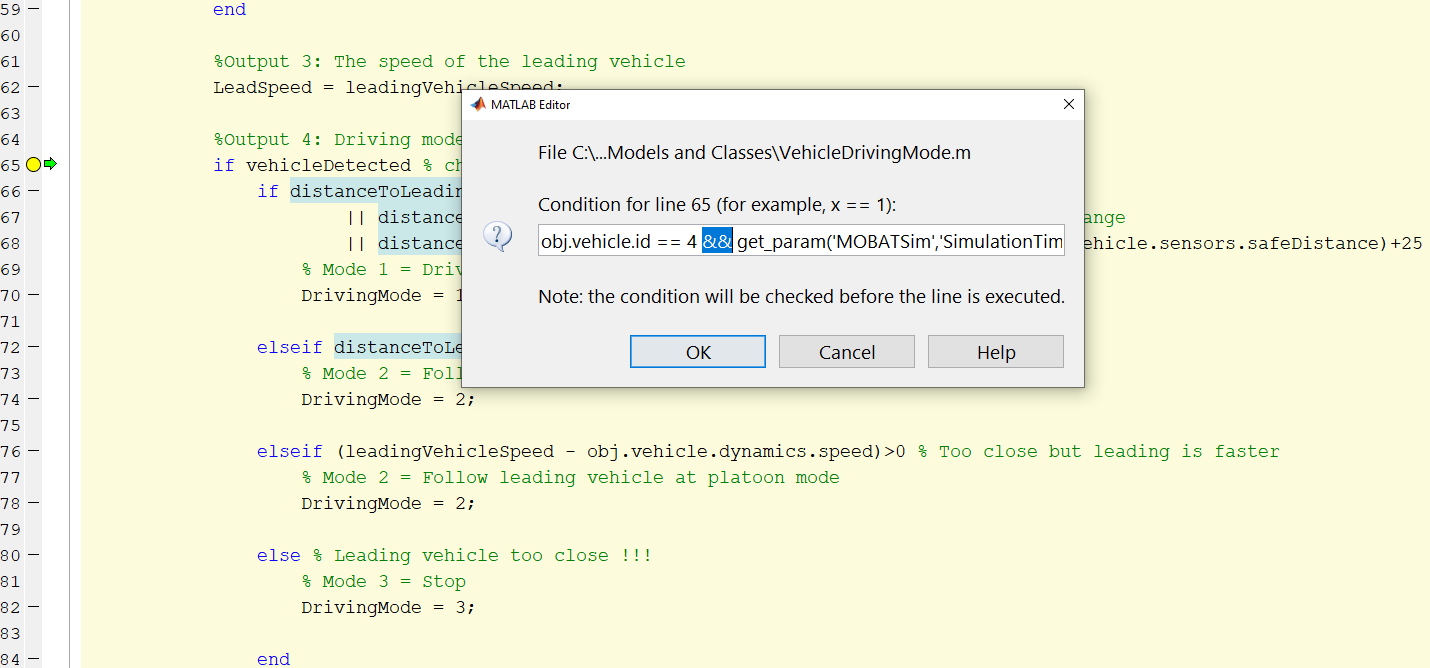

Now the yellow dot shows that the conditional breakpoint is set and all we have to do is to run the simulation. By executing the below code or just running the Simulink using the GUI, we will get to the Debugging mode.

Now you should see Debugging options marked with red below. The green arrow next to line number 65 indicates that we about to execute the code on line 65. At this moment, we can click on **Continue** or **Step** to continue executing the lines. However, in this task, we are going to check some states of **Vehicle 4** using the **Command Window** below.

## 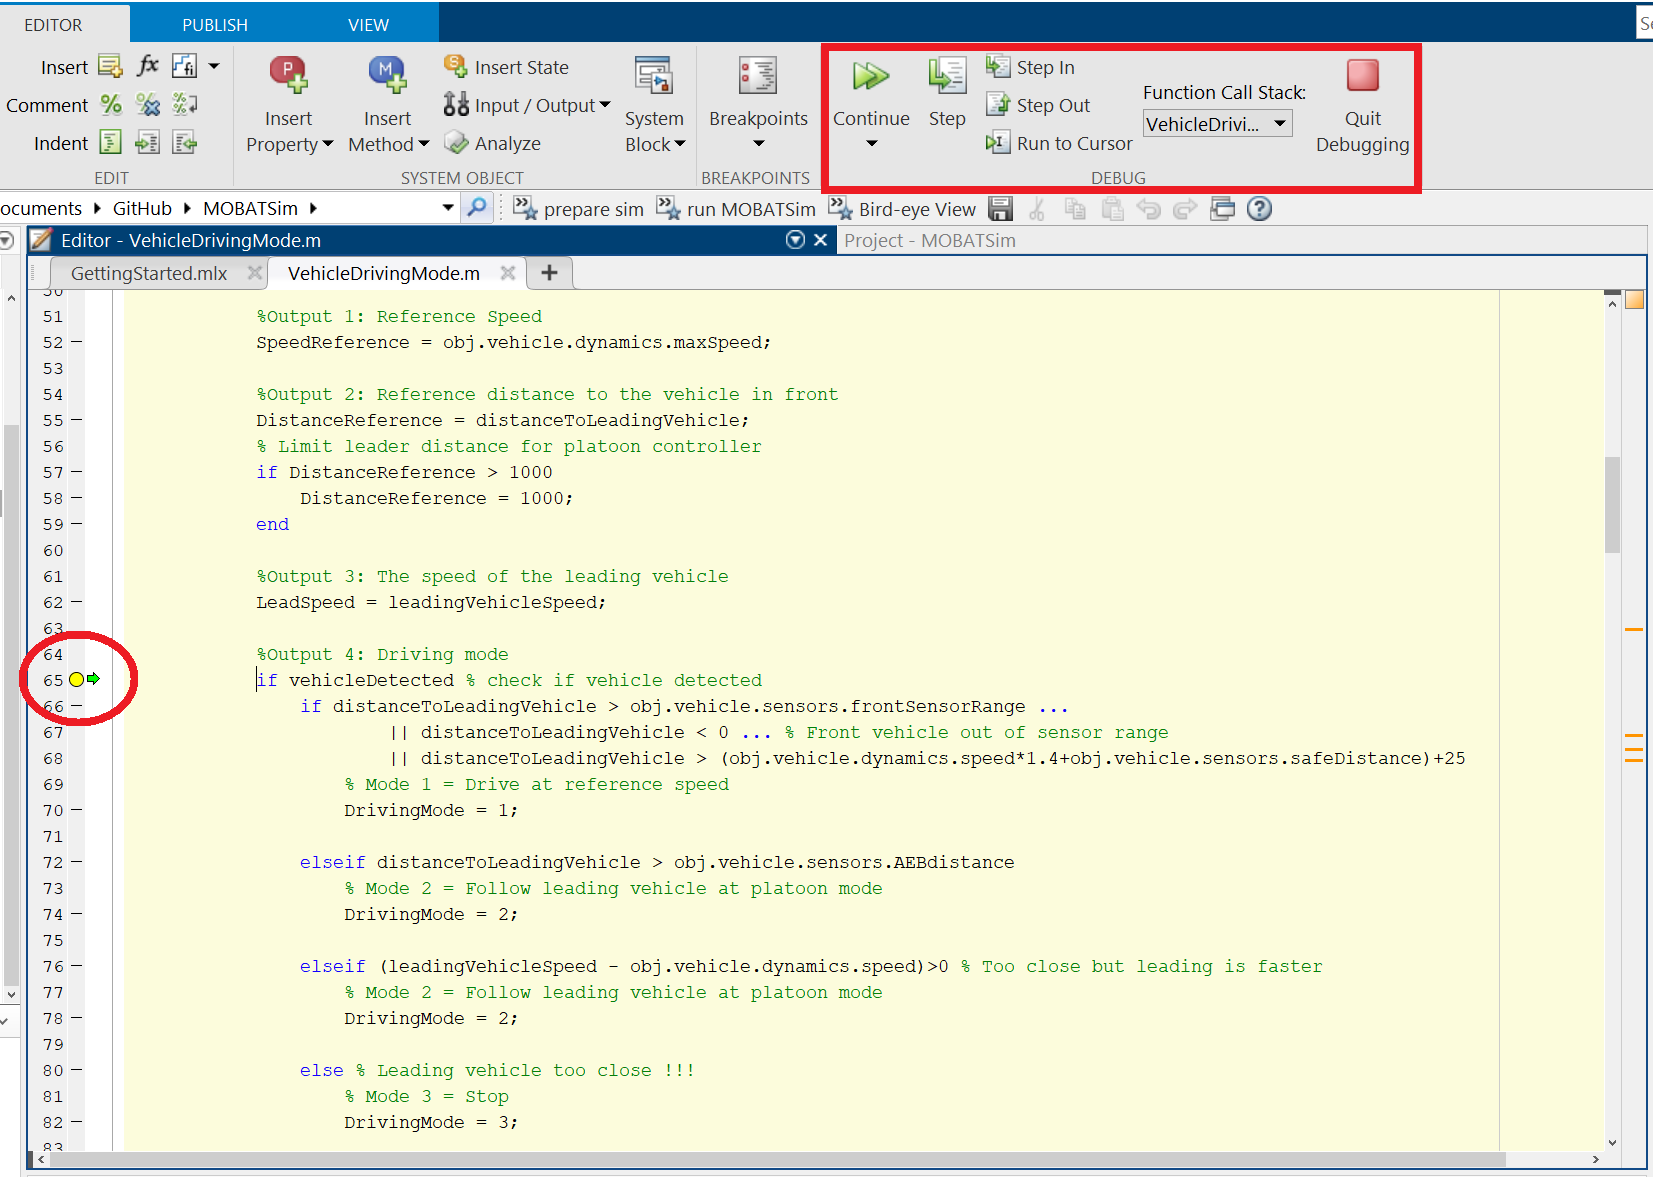

By typing `obj.vehicle.dynamics.speed `we check the current speed of **Vehicle 4** in m/s. To have a broader overlook to **Vehicle 4**, we can simply write `obj.vehicle` and we get the overlook of the structure of **Vehicle 4**. To learn more about the structure of a vehicle in MOBATSim, please refer to the class *src/Models and Classes/Vehicle.m*.

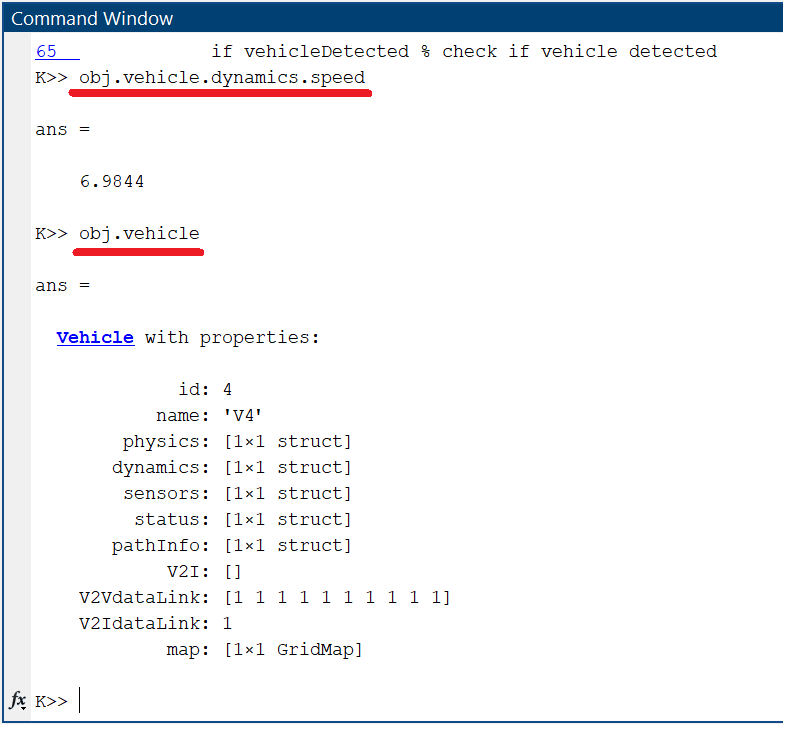

## 3- Change the Parameters of the Vehicle 2's Lateral Controller

In this Task, let's change **Vehicle 2**'s lateral controller parameters and see if there will be any change by the visualization. Firstly we need to navigate into the lateral controller subsystem.

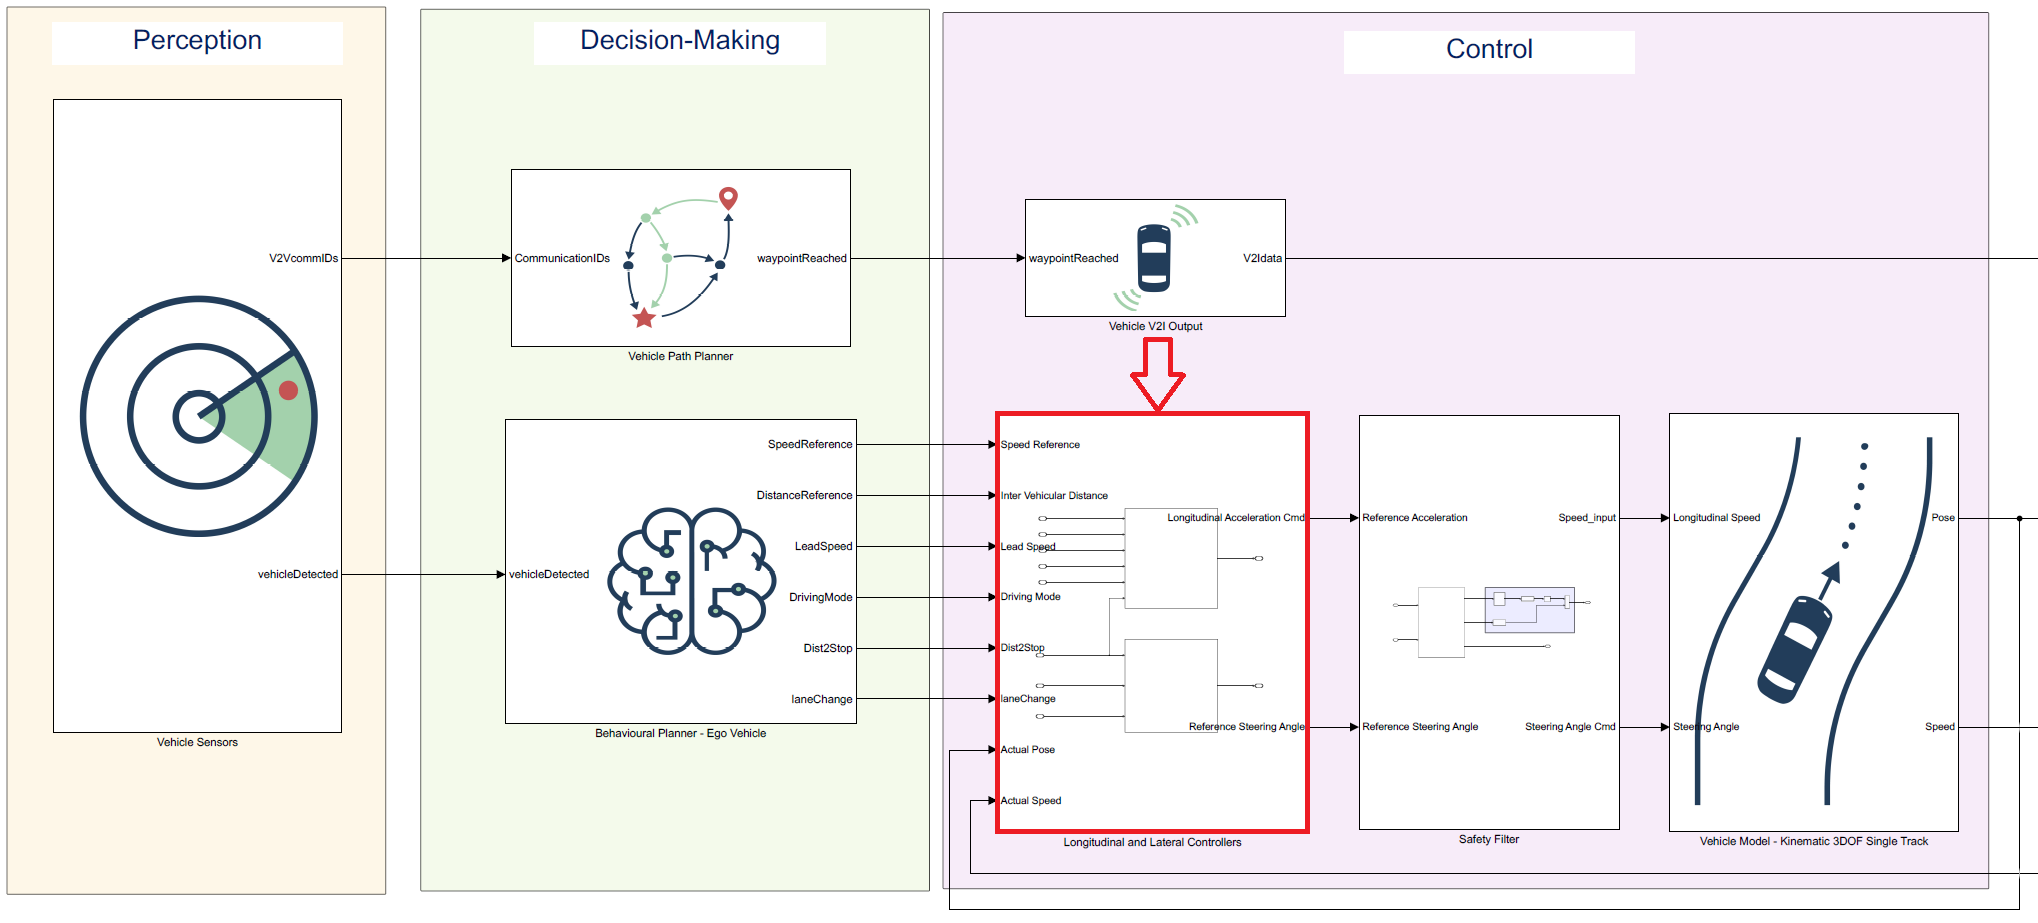

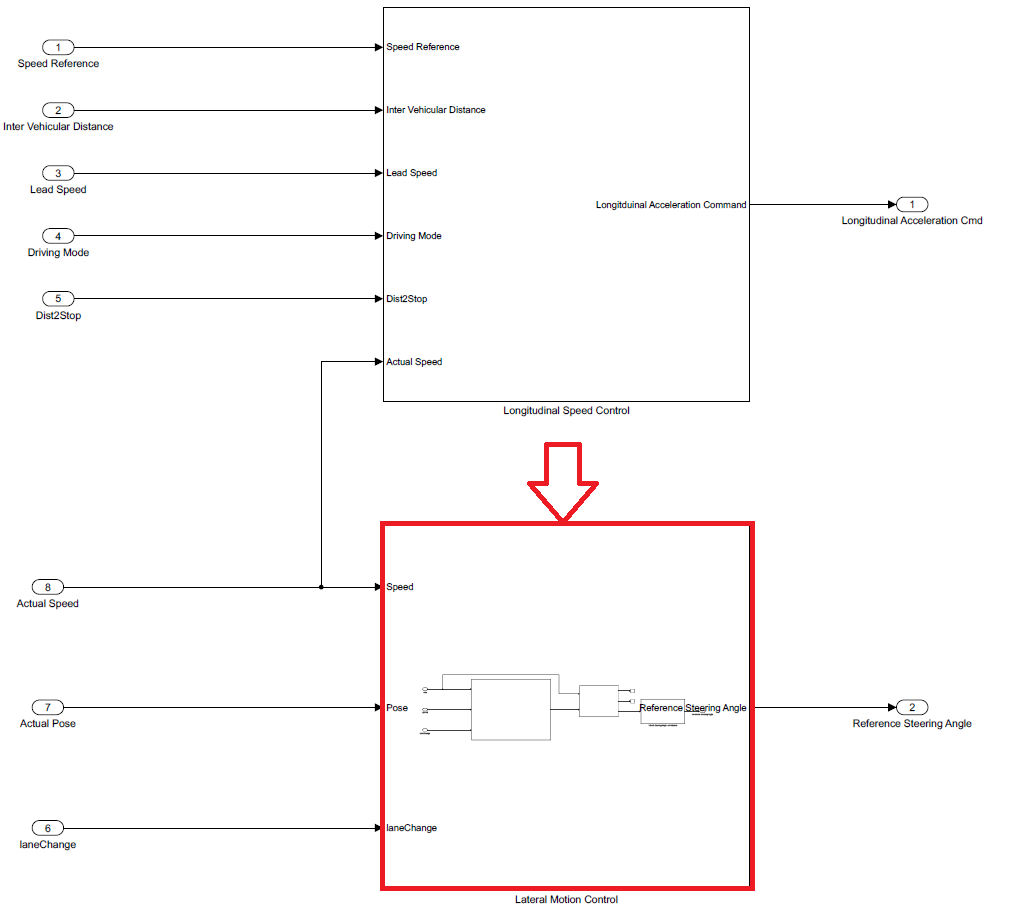

Here we have two blocks. First one is the **Pure Pursuit** **controller (1)** and the second one is a **subsystem (2)** which converts the reference direction into steering angle for the vehicle kinematic bicycle model.

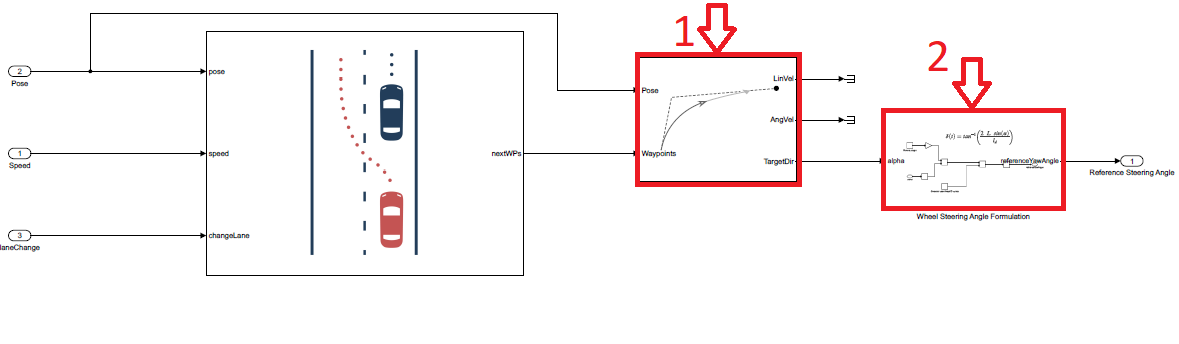

By clicking on the first block, we can directly set the parameters from the window. Here we can change the **maximum angular velocity** and make it smaller than **"1 rad/s"** to make the vehicle less capable of cornering. Normally this parameter depends on the vehicle size and other properties. However, the **lookahead distance** parameter for the **Pure Pursuit** controller is a design parameter that defines how sharply the vehicle turns. Making this value bigger makes the curves smoother but slower to turn; making it smaller makes the vehicle act quicker but do sharp movements, which may cause destabilization.

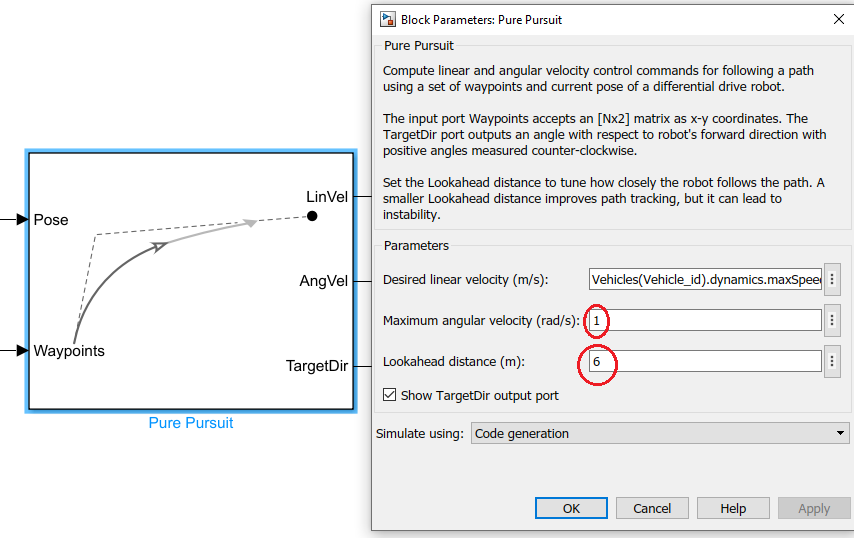

We enter another subsystem by clicking onto the second block where the conversion from direction angle alpha to steering angle happens. Here we can change the vehicle length according to the size of the vehicle, but more importantly, we should change the lookahead distance according to the formula as we changed in the previous section. In any case, you can test different values for the lookahead distance by changing the constant, running the simulation, visualizing how **Vehicle 2** turns, and then test other values.

## 4- Change the Path Planner Type of a Vehicle

Again from the Vehicle's Simulink Model, go to the Vehicle Path Planner block and right click on it. From the list choose the **Block Parameters (MATLABSystem) **option.

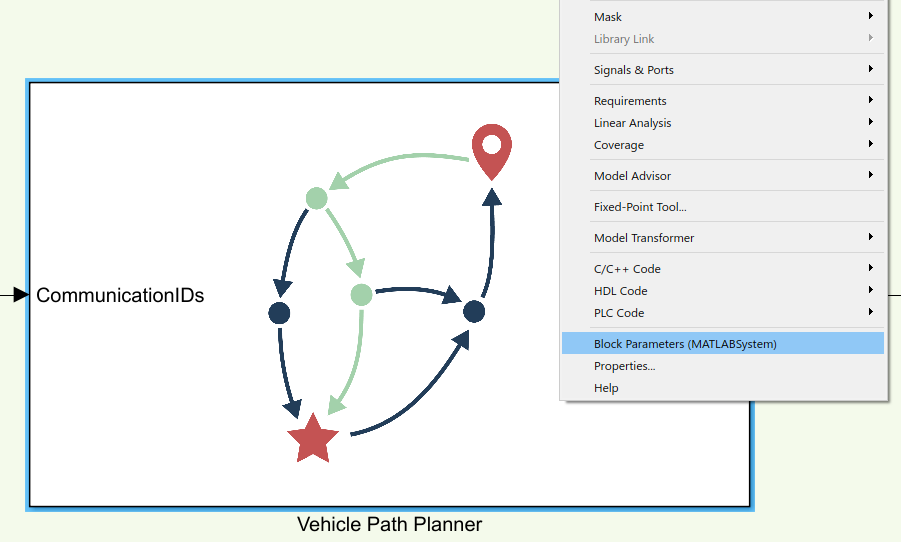

Inside, you can change the desired path planner class from **VehiclePathPlanner_Astar** to **VehiclePathPlanner_shortestPathFinder**.

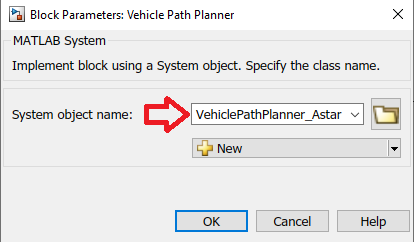

After you edited the class, you have to double click on the path planner block and change everything back to the version underneath.

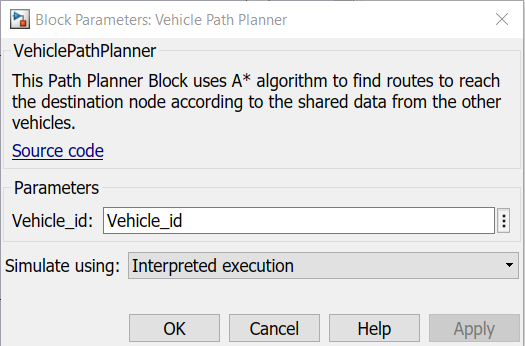

## 5- Inject Faults to Vehicle X during the Simulation

In this Task, we can simply edit the Simulink model of a vehicle that we would like to and add a white noise source to the reference speed signal. Fault injection can be used to alter any of the signals in Simulink; therefore, this is just a simple example of examining the effects of a white noise disturbance on the vehicle's speed.

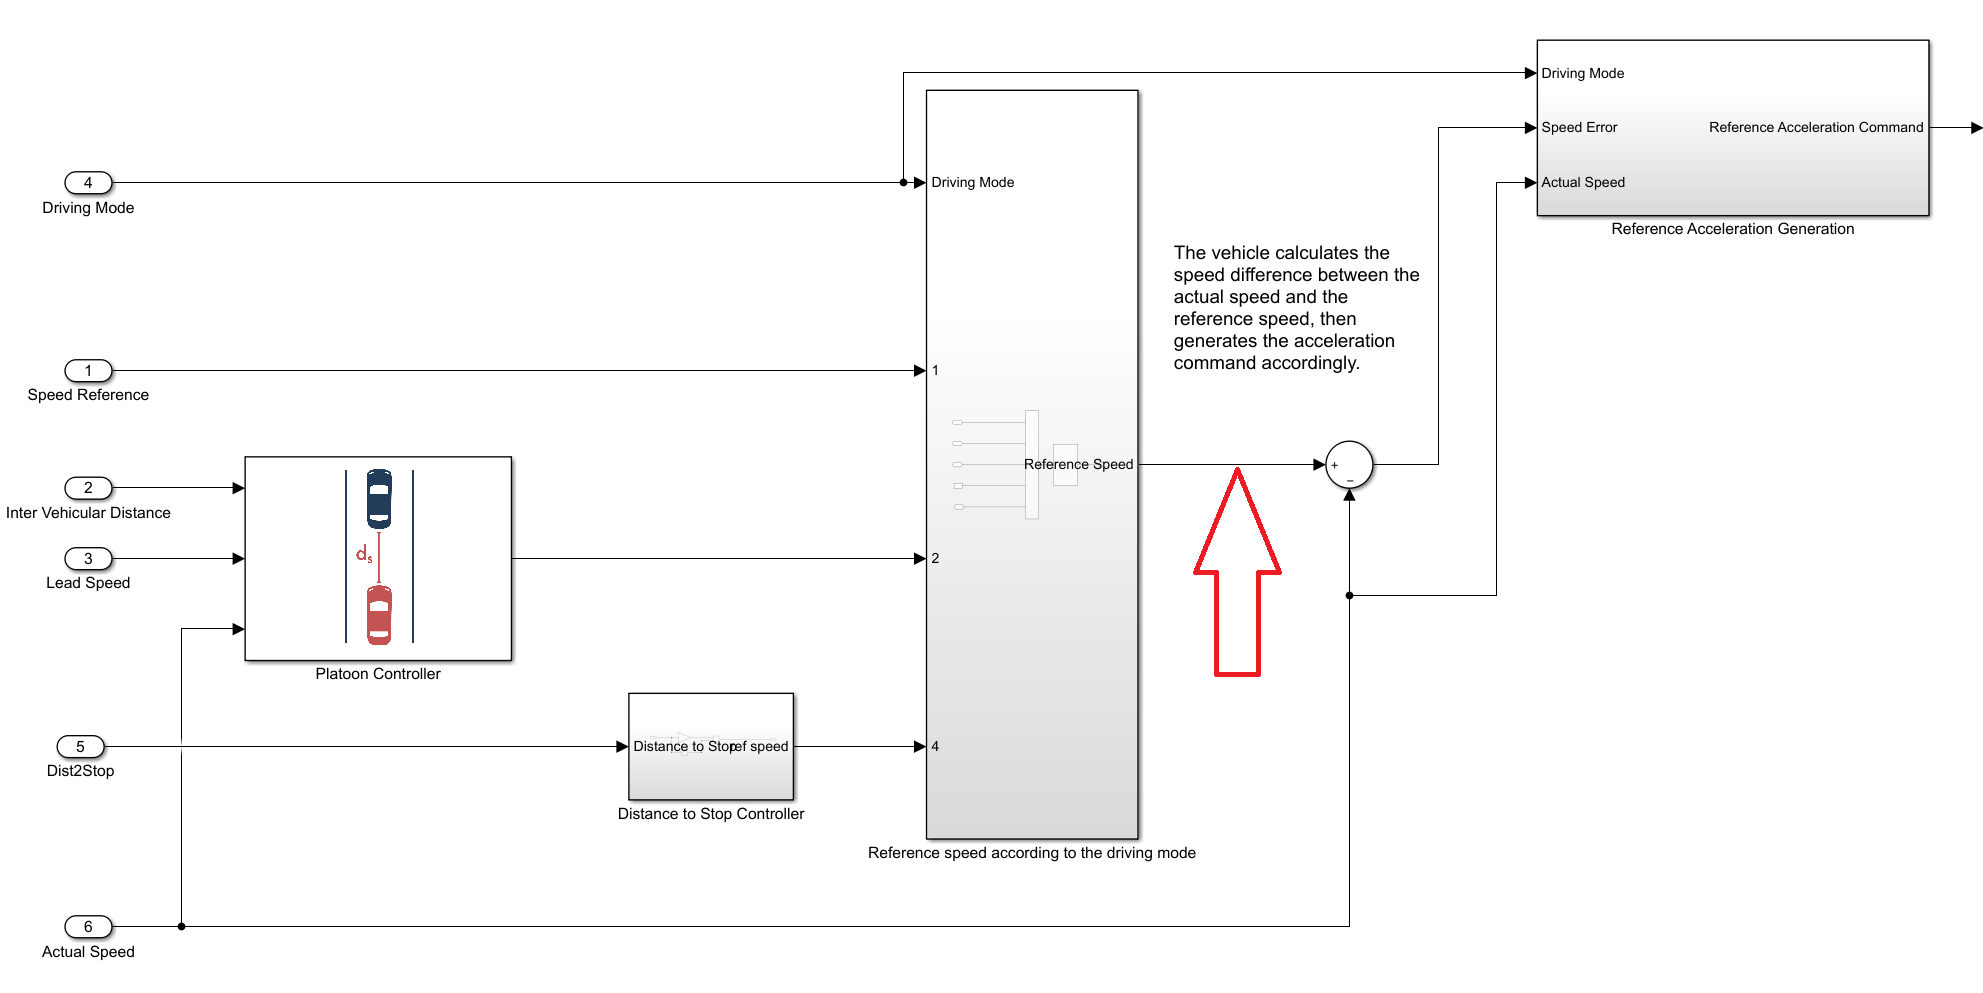

For the sake of simplicity, you can use a Band-Limited White Noise block and a sum block to inject faults. For more sophisticated fault injections, you can use a subsystem and/or a MATLAB function block.

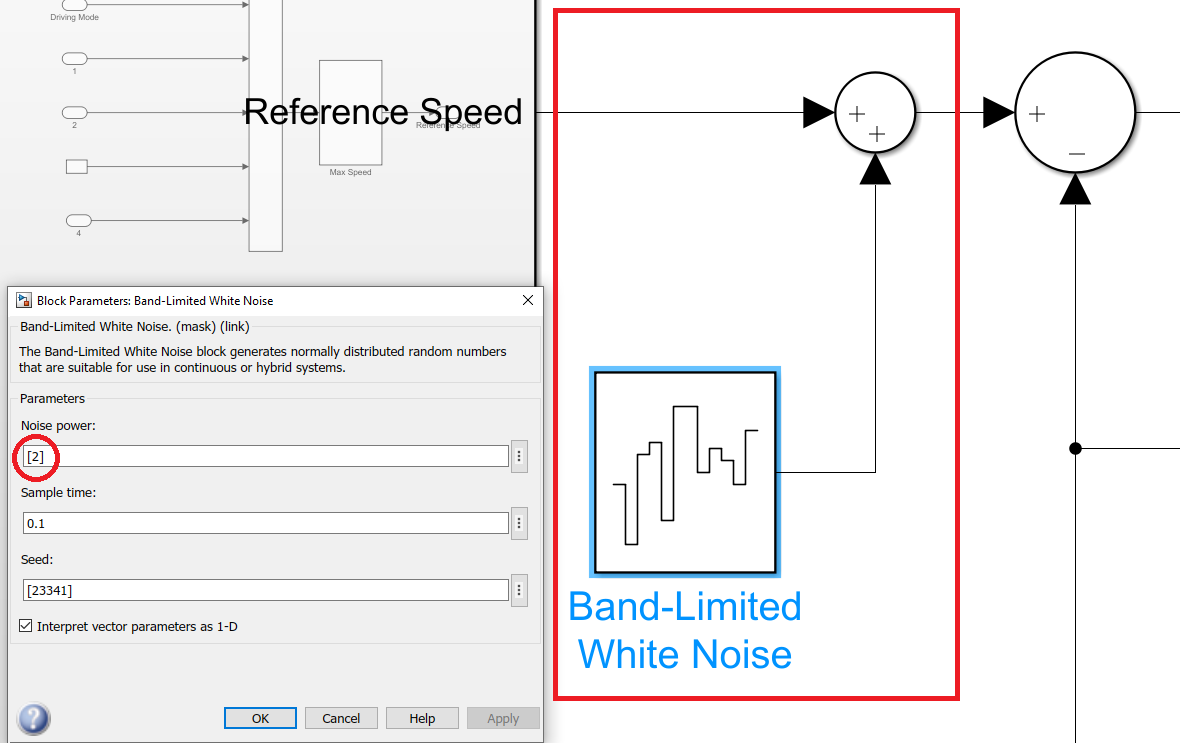

As we can see, even a noise with power **"2"** can cause higher deviations in the speed values.

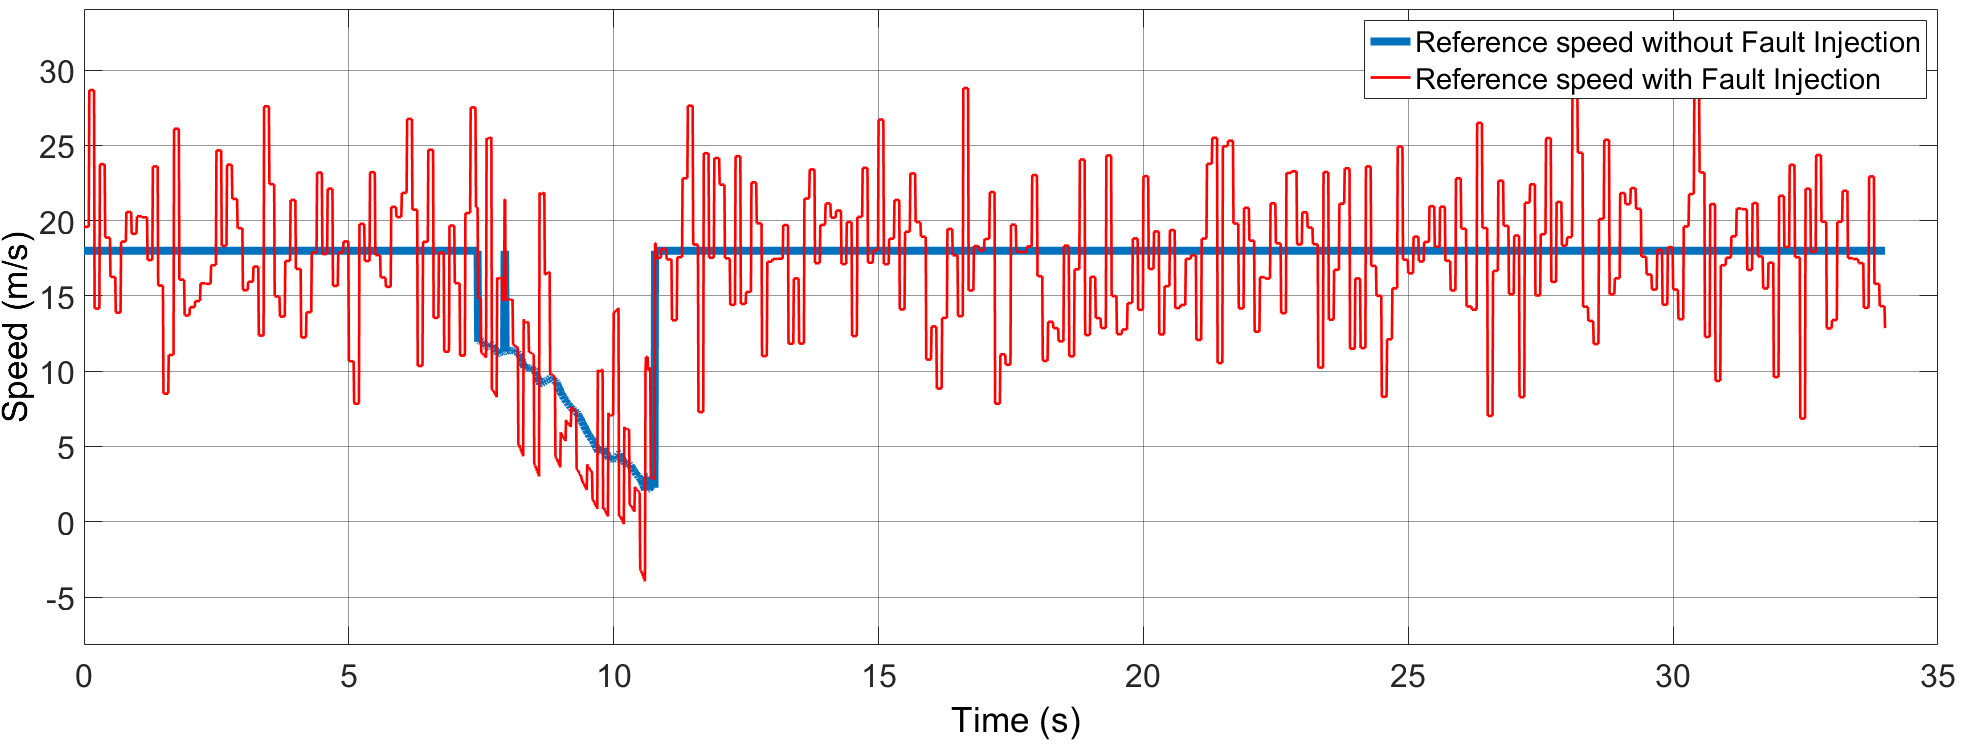

# -----------------------------------------------------------------------------

# Further Documentation

Please continue with the live script [Documentation.mlx](matlab:open('./docs\Documentation.mlx')) in the **docs** folder.